# Filter Sistem for ECG and RR

clearvars, clc

## Reading files

#### Bitalino

bitalino_Fs = 1000;

data = readtable("domingues01.txt");
bitalino_data1.ecg = table2array(data(:,"Var6"));
bitalino_data1.rr = table2array(data(:,"Var7"));
bitalino_data1.t = linspace(0,length(bitalino_data1.ecg)/bitalino_Fs,length(bitalino_data1.ecg))';

data = readtable("domingues02.txt");
bitalino_data2.ecg = table2array(data(:,"Var6"));
bitalino_data2.rr = table2array(data(:,"Var7"));
bitalino_data2.t = linspace(0,length(bitalino_data2.ecg)/bitalino_Fs,length(bitalino_data2.ecg))';

data = readtable("domingues03.txt");
bitalino_data3.ecg = table2array(data(:,"Var6"));
bitalino_data3.rr = table2array(data(:,"Var7"));
bitalino_data3.t = linspace(0,length(bitalino_data3.ecg)/bitalino_Fs,length(bitalino_data3.ecg))';

clear data

#### Accelerometer

data = readtable("domingues1.csv","VariableNamingRule","preserve");
accel_data1.z = table2array(data(:,"x_accel"));
accel_data1.t = table2array(data(:,"Hours:Minutes:Seconds.Milliseconds"));
accel_data1.t = seconds(accel_data1.t);
accel_data1.t = accel_data1.t - accel_data1.t(1);
accel_data1.fs = mean(1./diff(accel_data1.t));

data = readtable("domingues2.csv","VariableNamingRule","preserve");
accel_data2.z = table2array(data(:,"x_accel"));
accel_data2.t = table2array(data(:,"Hours:Minutes:Seconds.Milliseconds"));
accel_data2.t = seconds(accel_data2.t);
accel_data2.t = accel_data2.t - accel_data2.t(1);
accel_data2.fs = mean(1./diff(accel_data2.t));

data = readtable("domingues3.csv","VariableNamingRule","preserve");
accel_data3.z = table2array(data(:,"x_accel"));
accel_data3.t = table2array(data(:,"Hours:Minutes:Seconds.Milliseconds"));
accel_data3.t = seconds(accel_data3.t);
accel_data3.t = accel_data3.t - accel_data3.t(1);
accel_data3.fs = mean(1./diff(accel_data3.t));

clear data

#### Outputting graphs

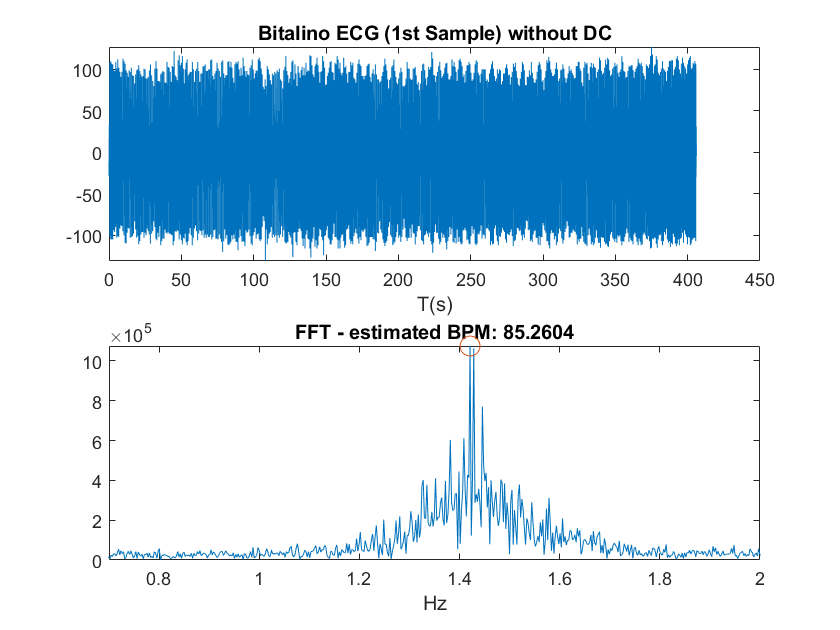

custom_fft(bitalino_data1.ecg-mean(bitalino_data1.ecg), bitalino_data1.t, bitalino_Fs, "Bitalino ECG (1st Sample) without DC", "BPM");

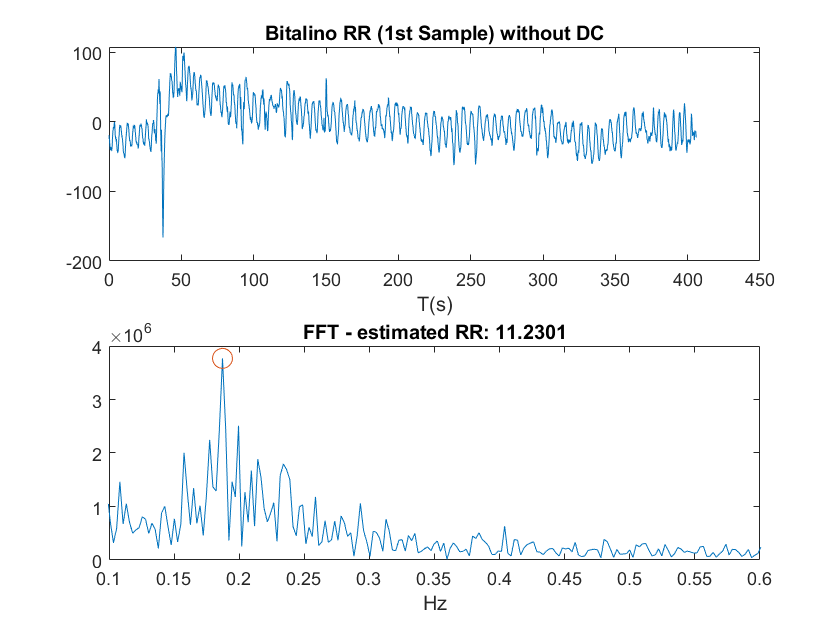

custom_fft(bitalino_data1.rr-mean(bitalino_data1.rr), bitalino_data1.t, bitalino_Fs, "Bitalino RR (1st Sample) without DC", "RR");

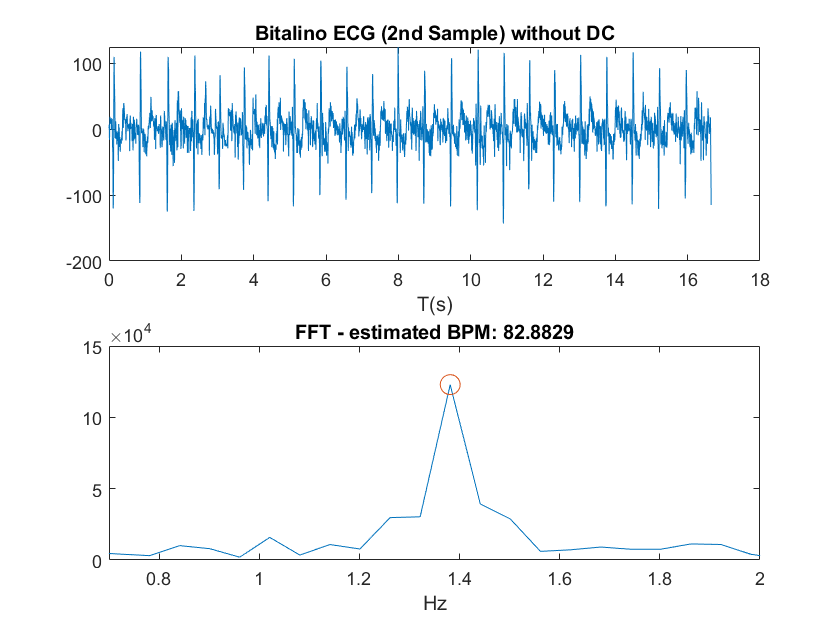

custom_fft(bitalino_data2.ecg-mean(bitalino_data2.ecg), bitalino_data2.t, bitalino_Fs, "Bitalino ECG (2nd Sample) without DC", "BPM");

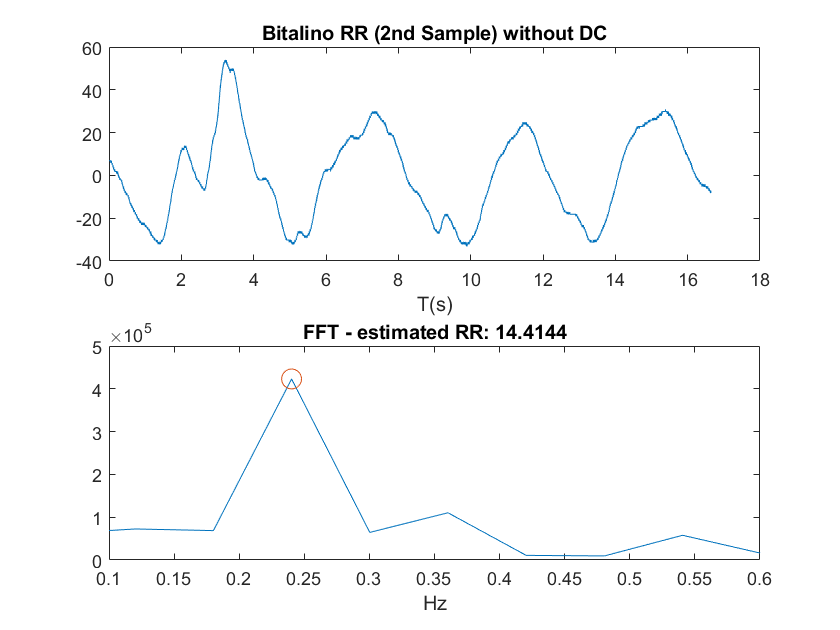

custom_fft(bitalino_data2.rr-mean(bitalino_data2.rr), bitalino_data2.t, bitalino_Fs, "Bitalino RR (2nd Sample) without DC", "RR");

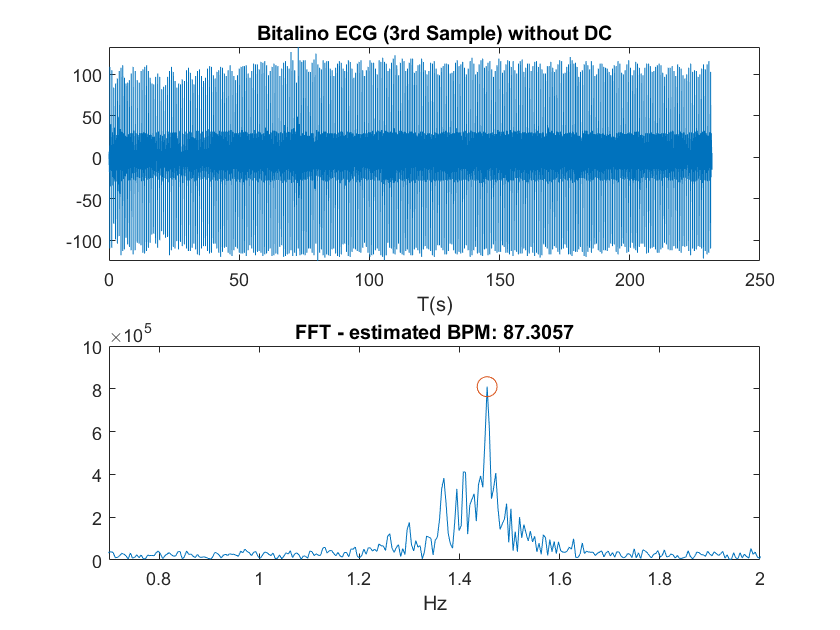

custom_fft(bitalino_data3.ecg-mean(bitalino_data3.ecg), bitalino_data3.t, bitalino_Fs, "Bitalino ECG (3rd Sample) without DC", "BPM");

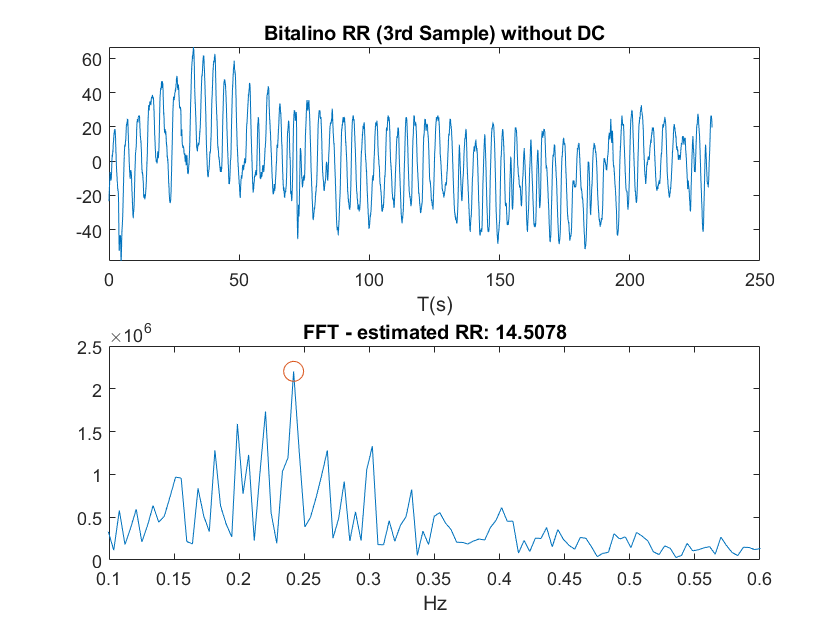

custom_fft(bitalino_data3.rr-mean(bitalino_data3.rr), bitalino_data3.t, bitalino_Fs, "Bitalino RR (3rd Sample) without DC", "RR");

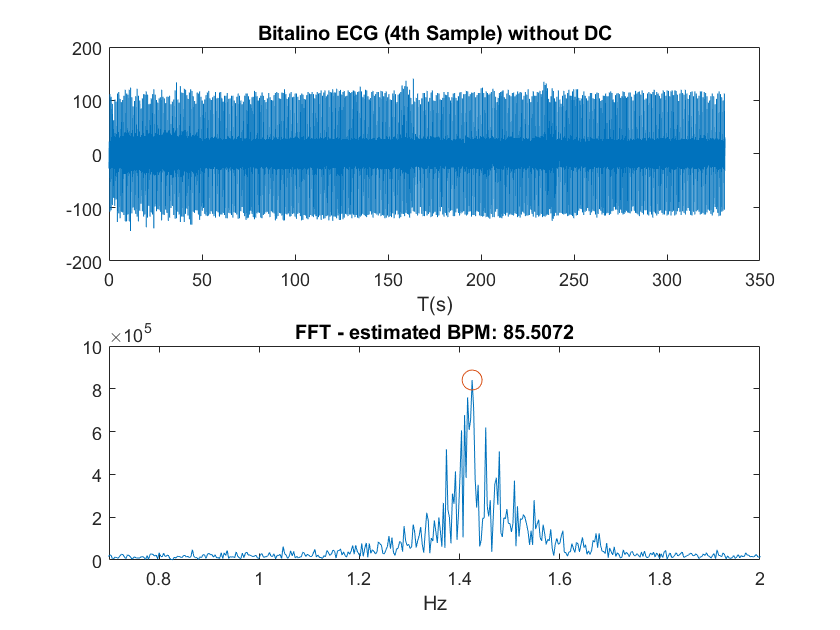

custom_fft(bitalino_data4.ecg-mean(bitalino_data4.ecg), bitalino_data4.t, bitalino_Fs, "Bitalino ECG (4th Sample) without DC", "BPM");

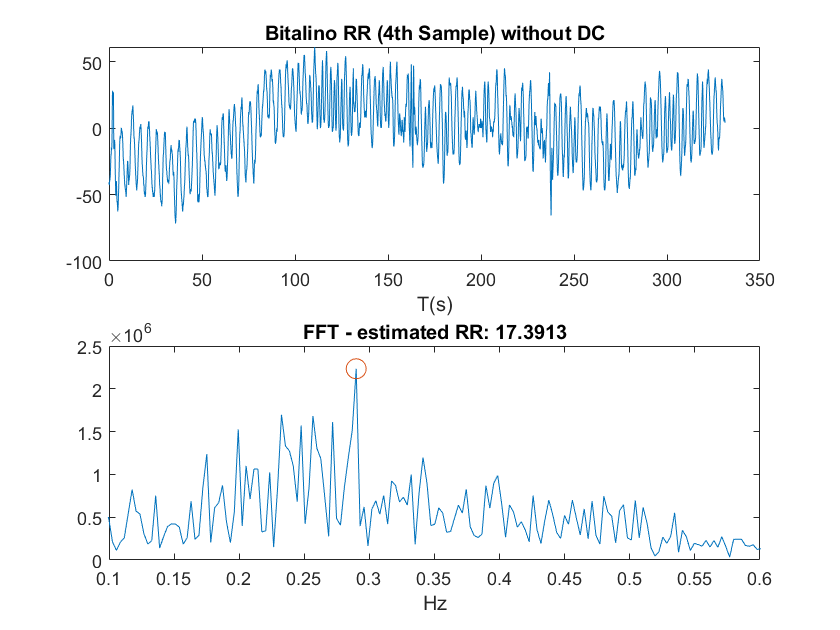

custom_fft(bitalino_data4.rr-mean(bitalino_data4.rr), bitalino_data4.t, bitalino_Fs, "Bitalino RR (4th Sample) without DC", "RR");

Estimated RR: 10.0229
Estimated BPM: 50.3714


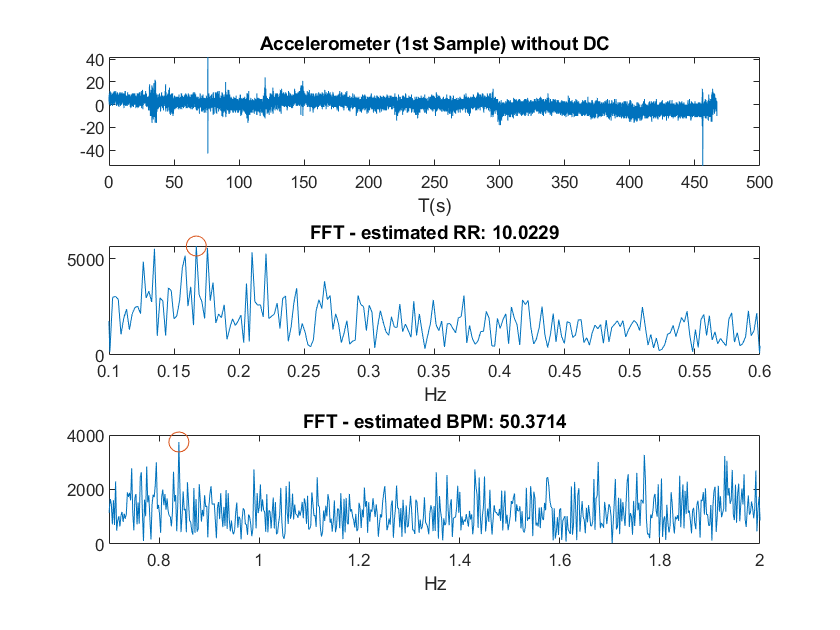


custom_fft(accel_data1.z-mean(accel_data1.z), accel_data1.t, accel_data1.fs, "Accelerometer (1st Sample) without DC", "ALL");

Estimated RR: 14.5566
Estimated BPM: 116.0368


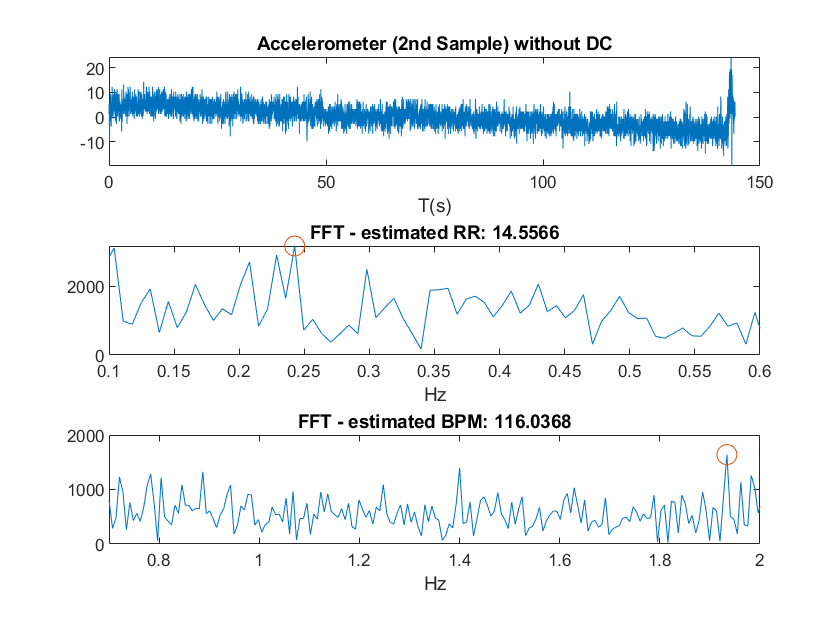

custom_fft(accel_data2.z-mean(accel_data2.z), accel_data2.t, accel_data2.fs, "Accelerometer (2nd Sample) without DC", "ALL");

Estimated RR: 6.0135
Estimated BPM: 113.2548


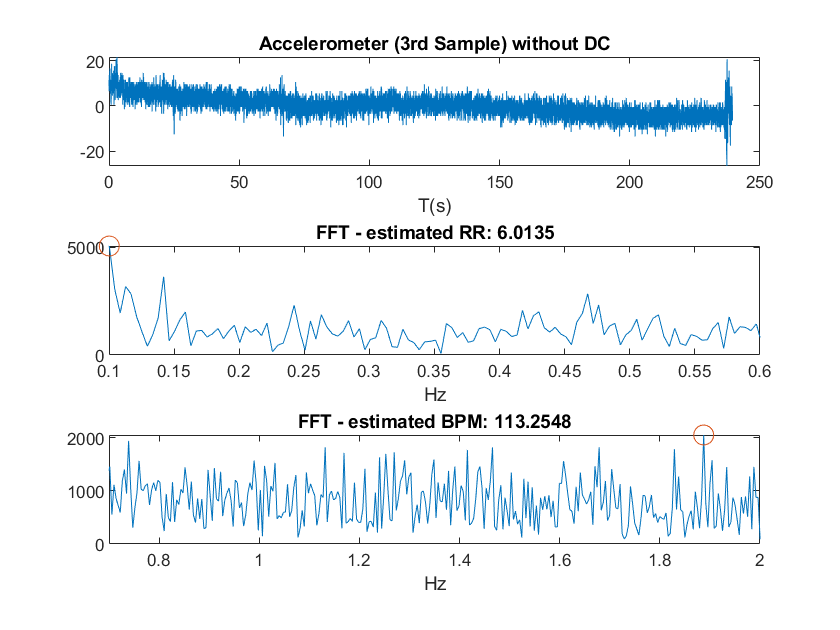

custom_fft(accel_data3.z-mean(accel_data3.z), accel_data3.t, accel_data3.fs, "Accelerometer (3rd Sample) without DC", "ALL");

Estimated RR: 13.5736
Estimated BPM: 60.0254


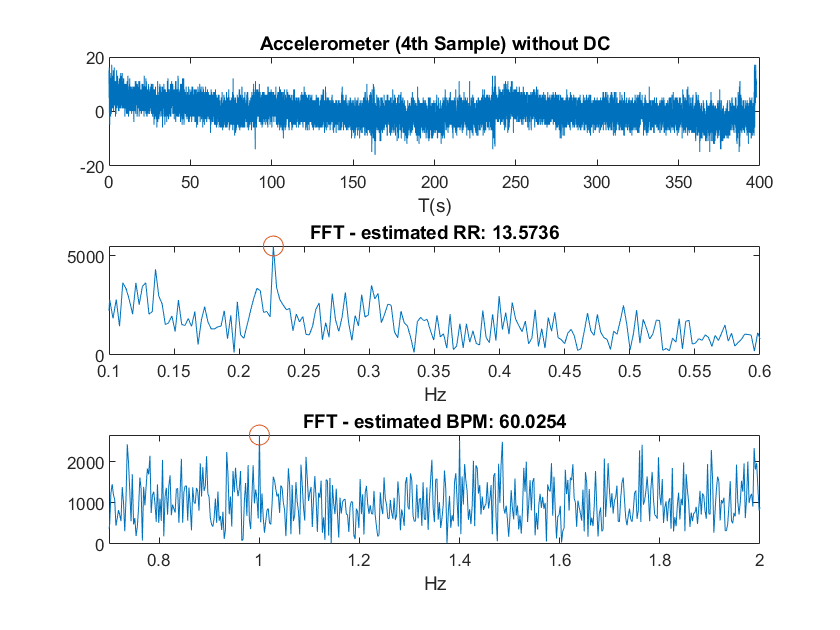

custom_fft(accel_data4.z-mean(accel_data4.z), accel_data4.t, accel_data4.fs, "Accelerometer (4th Sample) without DC", "ALL");

## Removing and Filling outliers

#### Bitalino sample 1

data_ecg = bitalino_data1.ecg;
data_rr = bitalino_data1.rr;
time = bitalino_data1.t;

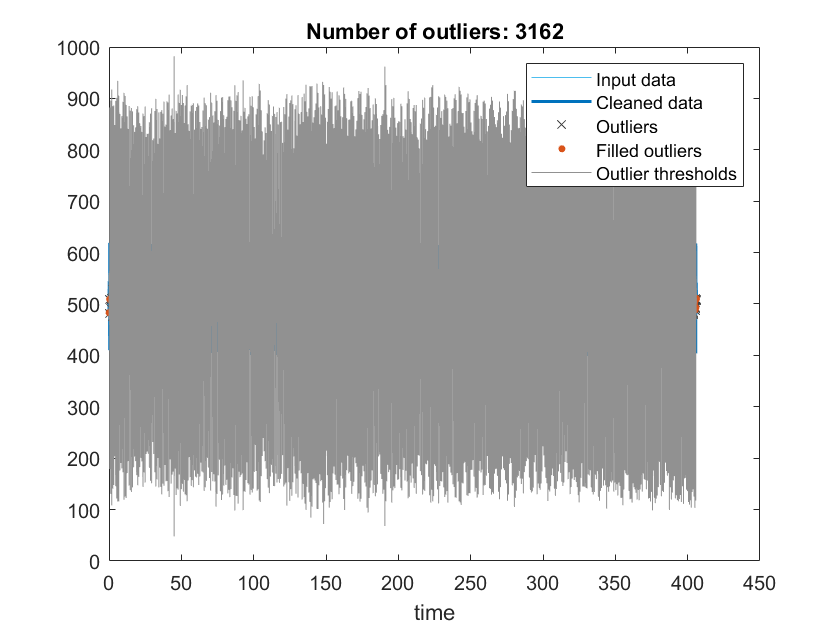

% Fill outliers
[cleanedECG,outlierIndices2,thresholdLow2,thresholdHigh2] = ...
    filloutliers(data_ecg,"linear","movmedian",0.027,"SamplePoints",time);

% Display results
clf
plot(time,data_ecg,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(time,cleanedECG,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Cleaned data")

% Plot outliers
plot(time(outlierIndices2),data_ecg(outlierIndices2),"x",...
    "Color",[64 64 64]/255,"DisplayName","Outliers")
title("Number of outliers: " + nnz(outlierIndices2))

% Plot filled outliers
plot(time(outlierIndices2),cleanedECG(outlierIndices2),".","MarkerSize",12,...
    "Color",[217 83 25]/255,"DisplayName","Filled outliers")

% Plot outlier thresholds
plot([time(:); missing; time(:)],[thresholdHigh2(:); missing; thresholdLow2(:)],...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

hold off
legend
xlabel("time")
clear outlierIndices2 thresholdLow2 thresholdHigh2
saveas(gcf,"output/Bitalino ECG (1st Sample) outliers.jpeg")

saveas(gcf,"output/Bitalino ECG (1st Sample) outliers.fig")

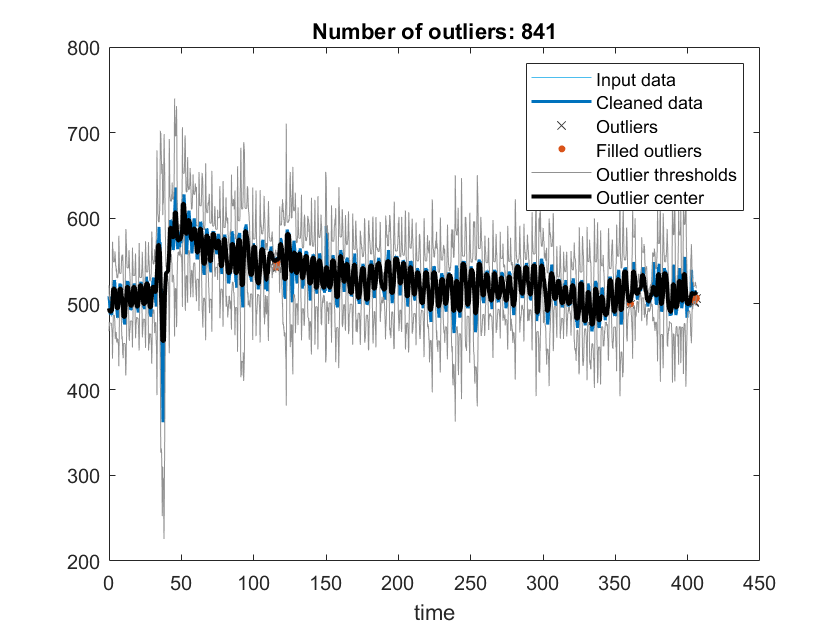

% Fill outliers
[cleanedRR,outlierIndices3,thresholdLow3,thresholdHigh3,center] = ...
    filloutliers(data_rr,"linear","movmedian",2.4,"SamplePoints",time);

% Display results
clf
plot(time,data_rr,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(time,cleanedRR,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Cleaned data")

% Plot outliers
plot(time(outlierIndices3),data_rr(outlierIndices3),"x","Color",[64 64 64]/255,...
    "DisplayName","Outliers")
title("Number of outliers: " + nnz(outlierIndices3))

% Plot filled outliers
plot(time(outlierIndices3),cleanedRR(outlierIndices3),".","MarkerSize",12,...
    "Color",[217 83 25]/255,"DisplayName","Filled outliers")

% Plot outlier thresholds
plot([time(:); missing; time(:)],[thresholdHigh3(:); missing; thresholdLow3(:)],...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

% Plot outlier center
plot(time,center,"k","LineWidth",2,"DisplayName","Outlier center")

hold off
legend
xlabel("time")
clear outlierIndices3 thresholdLow3 thresholdHigh3 center
saveas(gcf,"output/Bitalino RR (1st Sample) outliers.jpeg")

saveas(gcf,"output/Bitalino RR (1st Sample) outliers.fig")
bitalino_data1.ecg_step1 = cleanedECG;
bitalino_data1.rr_step1 = cleanedRR;
clear cleanedECG cleanedRR data_ecg data_rr time

#### Bitalino sample 2

data_ecg = bitalino_data2.ecg;
data_rr = bitalino_data2.rr;
time = bitalino_data2.t;

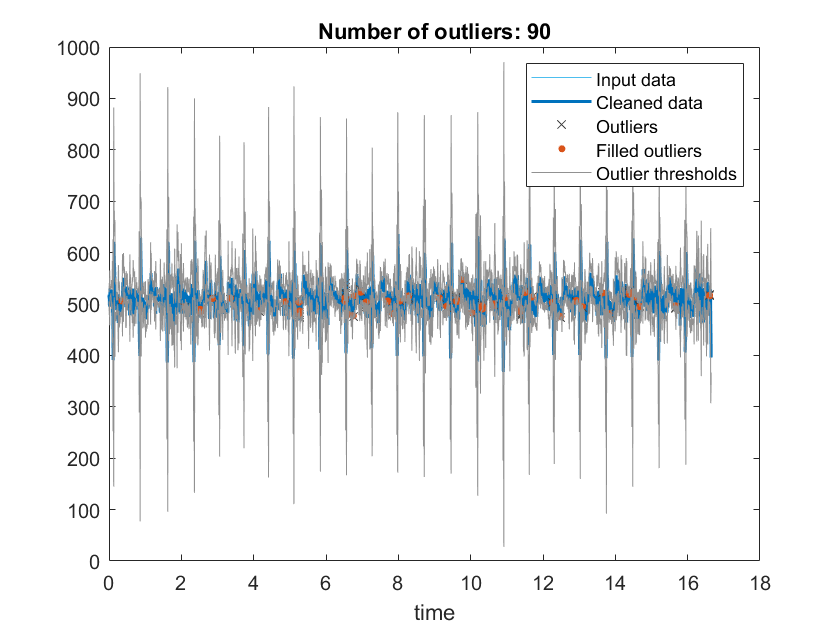

% Fill outliers
[cleanedECG,outlierIndices4,thresholdLow4,thresholdHigh4] = ...
    filloutliers(data_ecg,"linear","movmedian",0.024,"SamplePoints",time);

% Display results
clf
plot(time,data_ecg,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(time,cleanedECG,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Cleaned data")

% Plot outliers
plot(time(outlierIndices4),data_ecg(outlierIndices4),"x",...
    "Color",[64 64 64]/255,"DisplayName","Outliers")
title("Number of outliers: " + nnz(outlierIndices4))

% Plot filled outliers
plot(time(outlierIndices4),cleanedECG(outlierIndices4),".","MarkerSize",12,...
    "Color",[217 83 25]/255,"DisplayName","Filled outliers")

% Plot outlier thresholds
plot([time(:); missing; time(:)],[thresholdHigh4(:); missing; thresholdLow4(:)],...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

hold off
legend
xlabel("time")
clear outlierIndices4 thresholdLow4 thresholdHigh4
saveas(gcf,"output/Bitalino ECG (2nd Sample) outliers.jpeg")

saveas(gcf,"output/Bitalino ECG (2nd Sample) outliers.fig")

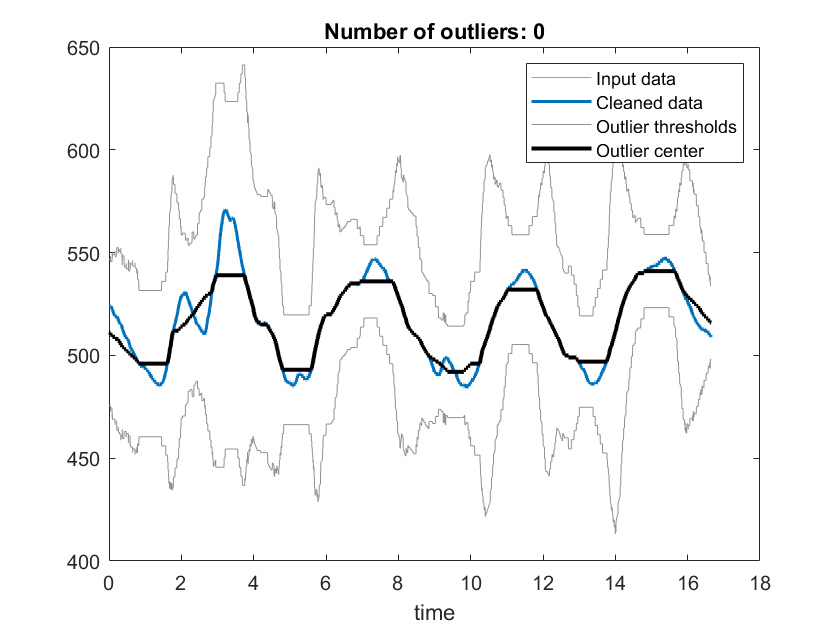

% Fill outliers
[cleanedRR,outlierIndices8,thresholdLow8,thresholdHigh8,center2] = ...
    filloutliers(data_rr,"linear","movmedian",1.6,"SamplePoints",time);

% Display results
clf
plot(time,data_rr,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(time,cleanedRR,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Cleaned data")

% Plot outliers
plot(time(outlierIndices8),data_rr(outlierIndices8),"x","Color",[64 64 64]/255,...
    "DisplayName","Outliers")
title("Number of outliers: " + nnz(outlierIndices8))

% Plot filled outliers
plot(time(outlierIndices8),cleanedRR(outlierIndices8),".","MarkerSize",12,...
    "Color",[217 83 25]/255,"DisplayName","Filled outliers")

% Plot outlier thresholds
plot([time(:); missing; time(:)],[thresholdHigh8(:); missing; thresholdLow8(:)],...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

% Plot outlier center
plot(time,center2,"k","LineWidth",2,"DisplayName","Outlier center")

hold off
legend
xlabel("time")
clear outlierIndices8 thresholdLow8 thresholdHigh8 center2
saveas(gcf,"output/Bitalino RR (2nd Sample) outliers.jpeg")

saveas(gcf,"output/Bitalino RR (2nd Sample) outliers.fig")
bitalino_data2.ecg_step1 = cleanedECG;
bitalino_data2.rr_step1 = cleanedRR;
clear cleanedECG cleanedRR data_ecg data_rr time

#### Bitalino sample 3

data_ecg = bitalino_data3.ecg;
data_rr = bitalino_data3.rr;
time = bitalino_data3.t;

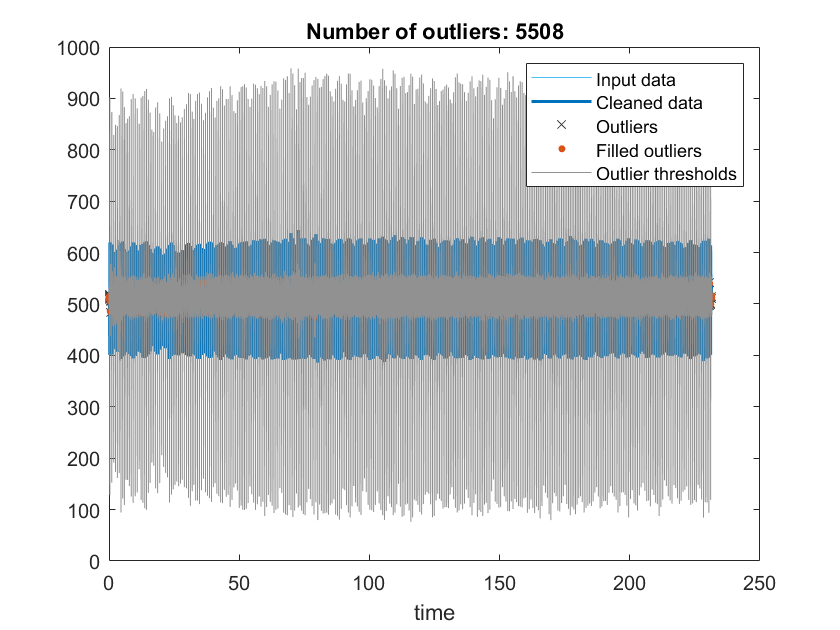

% Fill outliers
[cleanedECG,outlierIndices5,thresholdLow5,thresholdHigh5] = ...
    filloutliers(data_ecg,"linear","movmedian",0.027,"SamplePoints",time);

% Display results
clf
plot(time,data_ecg,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(time,cleanedECG,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Cleaned data")

% Plot outliers
plot(time(outlierIndices5),data_ecg(outlierIndices5),"x",...
    "Color",[64 64 64]/255,"DisplayName","Outliers")
title("Number of outliers: " + nnz(outlierIndices5))

% Plot filled outliers
plot(time(outlierIndices5),cleanedECG(outlierIndices5),".","MarkerSize",12,...
    "Color",[217 83 25]/255,"DisplayName","Filled outliers")

% Plot outlier thresholds
plot([time(:); missing; time(:)],[thresholdHigh5(:); missing; thresholdLow5(:)],...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

hold off
legend
xlabel("time")
clear outlierIndices5 thresholdLow5 thresholdHigh5
saveas(gcf,"output/Bitalino ECG (3rd Sample) outliers.jpeg")

saveas(gcf,"output/Bitalino ECG (3rd Sample) outliers.fig")

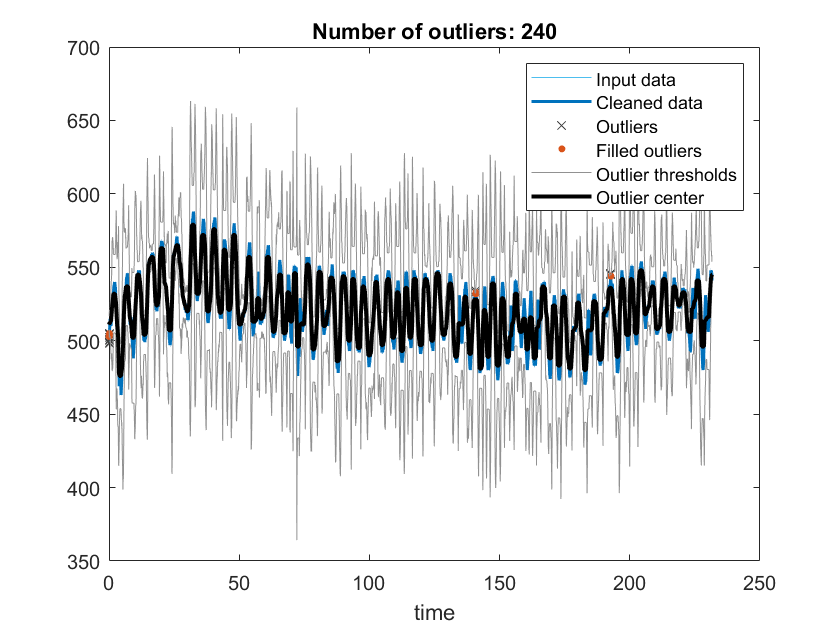

% Fill outliers
[cleanedRR,outlierIndices6,thresholdLow6,thresholdHigh6,center3] = ...
    filloutliers(data_rr,"linear","movmedian",1.7,"SamplePoints",time);

% Display results
clf
plot(time,data_rr,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(time,cleanedRR,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Cleaned data")

% Plot outliers
plot(time(outlierIndices6),data_rr(outlierIndices6),"x","Color",[64 64 64]/255,...
    "DisplayName","Outliers")
title("Number of outliers: " + nnz(outlierIndices6))

% Plot filled outliers
plot(time(outlierIndices6),cleanedRR(outlierIndices6),".","MarkerSize",12,...
    "Color",[217 83 25]/255,"DisplayName","Filled outliers")

% Plot outlier thresholds
plot([time(:); missing; time(:)],[thresholdHigh6(:); missing; thresholdLow6(:)],...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

% Plot outlier center
plot(time,center3,"k","LineWidth",2,"DisplayName","Outlier center")

hold off
legend
xlabel("time")
clear outlierIndices6 thresholdLow6 thresholdHigh6 center3
saveas(gcf,"output/Bitalino RR (3rd Sample) outliers.jpeg")

saveas(gcf,"output/Bitalino RR (3rd Sample) outliers.fig")
bitalino_data3.ecg_step1 = cleanedECG;
bitalino_data3.rr_step1 = cleanedRR;
clear cleanedECG cleanedRR data_ecg data_rr time

#### Bitalino sample 4

data_ecg = bitalino_data4.ecg;
data_rr = bitalino_data4.rr

data_rr =    478
   478
   478
   478
   478
   478
   478
   478
   478
   478


time = bitalino_data4.t;

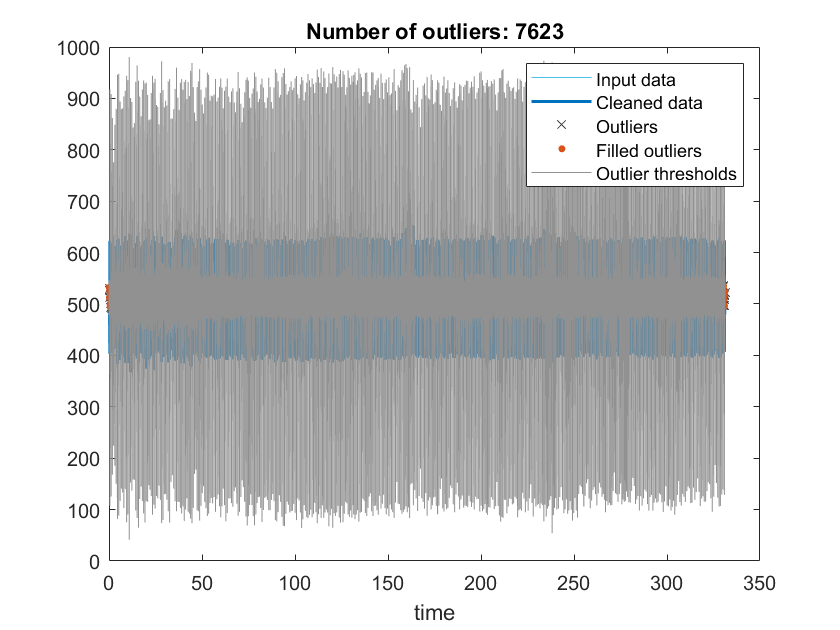

% Fill outliers
[cleanedECG,outlierIndices7,thresholdLow7,thresholdHigh7] = ...
    filloutliers(data_ecg,"linear","movmedian",0.027,"SamplePoints",time);

% Display results
clf
plot(time,data_ecg,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(time,cleanedECG,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Cleaned data")

% Plot outliers
plot(time(outlierIndices7),data_ecg(outlierIndices7),"x",...
    "Color",[64 64 64]/255,"DisplayName","Outliers")
title("Number of outliers: " + nnz(outlierIndices7))

% Plot filled outliers
plot(time(outlierIndices7),cleanedECG(outlierIndices7),".","MarkerSize",12,...
    "Color",[217 83 25]/255,"DisplayName","Filled outliers")

% Plot outlier thresholds
plot([time(:); missing; time(:)],[thresholdHigh7(:); missing; thresholdLow7(:)],...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

hold off
legend
xlabel("time")
clear outlierIndices7 thresholdLow7 thresholdHigh7
saveas(gcf,"output/Bitalino ECG (4th Sample) outliers.jpeg")

saveas(gcf,"output/Bitalino ECG (4th Sample) outliers.fig")

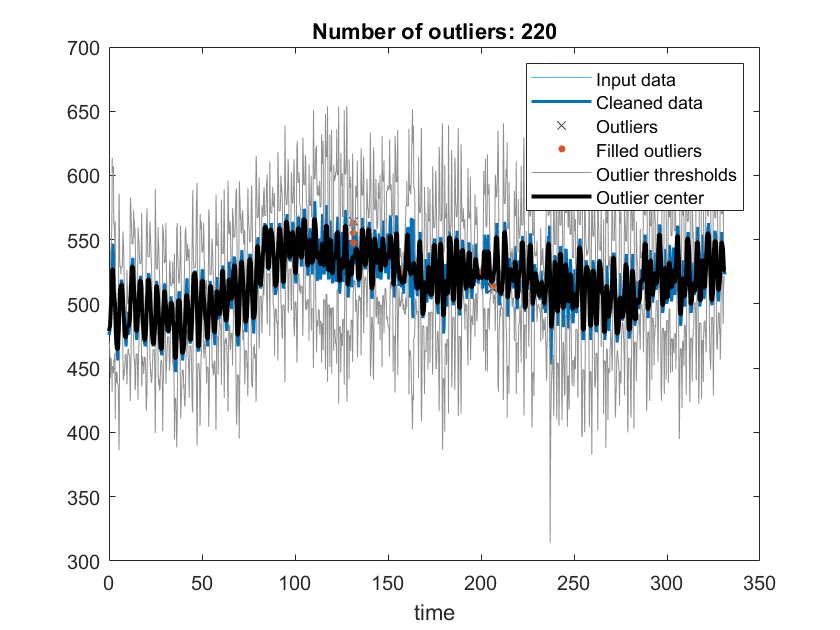

% Fill outliers
[cleanedRR,outlierIndices,thresholdLow,thresholdHigh,center4] = ...
    filloutliers(data_rr,"linear","movmedian",1.5,"SamplePoints",time);

% Display results
clf
plot(time,data_rr,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(time,cleanedRR,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Cleaned data")

% Plot outliers
plot(time(outlierIndices),data_rr(outlierIndices),"x","Color",[64 64 64]/255,...
    "DisplayName","Outliers")
title("Number of outliers: " + nnz(outlierIndices))

% Plot filled outliers
plot(time(outlierIndices),cleanedRR(outlierIndices),".","MarkerSize",12,...
    "Color",[217 83 25]/255,"DisplayName","Filled outliers")

% Plot outlier thresholds
plot([time(:); missing; time(:)],[thresholdHigh(:); missing; thresholdLow(:)],...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

% Plot outlier center
plot(time,center4,"k","LineWidth",2,"DisplayName","Outlier center")

hold off
legend
xlabel("time")
clear outlierIndices thresholdLow thresholdHigh center4
saveas(gcf,"output/Bitalino RR (4th Sample) outliers.jpeg")

saveas(gcf,"output/Bitalino RR (4th Sample) outliers.fig")
bitalino_data4.ecg_step1 = cleanedECG;
bitalino_data4.rr_step1 = cleanedRR;
clear cleanedECG cleanedRR data_ecg data_rr time

#### Accelerometer sample 1

data = accel_data1.z;
time = accel_data1.t;

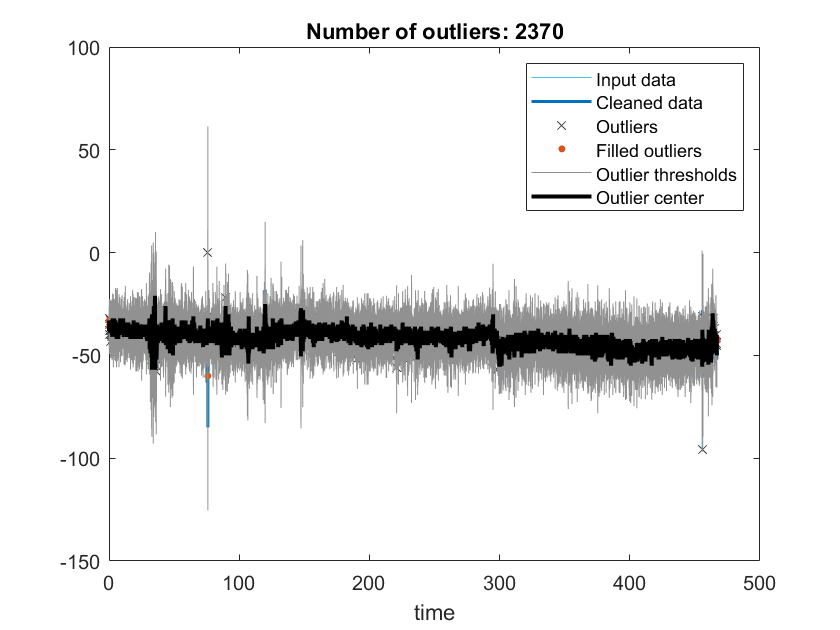

% Fill outliers
[cleanedData,outlierIndices9,thresholdLow9,thresholdHigh9,center9] = ...
    filloutliers(data,"linear","movmedian",0.065,"SamplePoints",time);

% Display results
clf
plot(time,data,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(time,cleanedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Cleaned data")

% Plot outliers
plot(time(outlierIndices9),data(outlierIndices9),"x","Color",[64 64 64]/255,...
    "DisplayName","Outliers")
title("Number of outliers: " + nnz(outlierIndices9))

% Plot filled outliers
plot(time(outlierIndices9),cleanedData(outlierIndices9),".","MarkerSize",12,...
    "Color",[217 83 25]/255,"DisplayName","Filled outliers")

% Plot outlier thresholds
plot([time(:); missing; time(:)],[thresholdHigh9(:); missing; thresholdLow9(:)],...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

% Plot outlier center
plot(time,center9,"k","LineWidth",2,"DisplayName","Outlier center")

hold off
legend
xlabel("time")
clear outlierIndices9 thresholdLow9 thresholdHigh9 center9
saveas(gcf,"output/Accelerometer (1st Sample) outliers.jpeg")

saveas(gcf,"output/Accelerometer (1st Sample) outliers.fig")
accel_data1.step1 = cleanedData;
clear cleanedData data time

#### Accelerometer sample 2

data = accel_data2.z;
time = accel_data2.t;

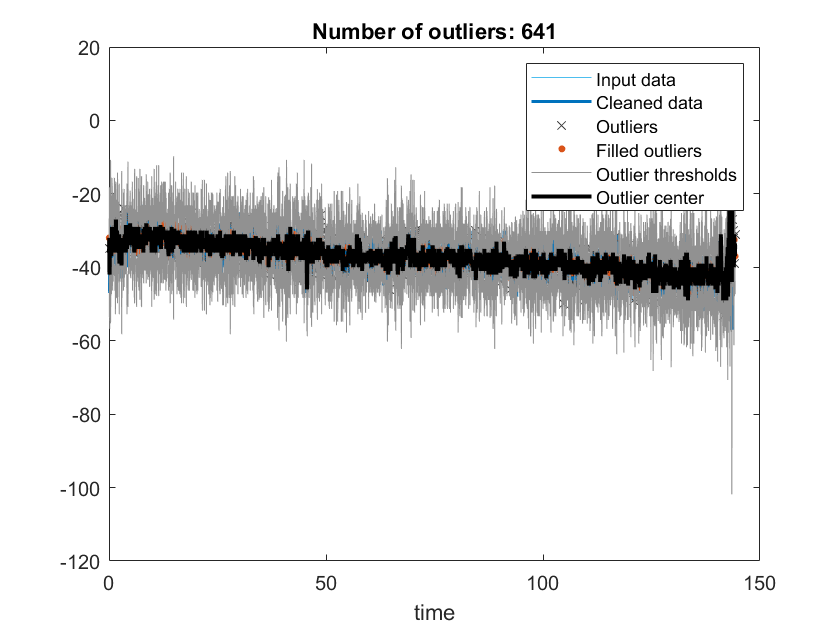

% Fill outliers
[cleanedData,outlierIndices10,thresholdLow10,thresholdHigh10,center10] = ...
    filloutliers(data,"linear","movmedian",0.065,"SamplePoints",time);

% Display results
clf
plot(time,data,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(time,cleanedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Cleaned data")

% Plot outliers
plot(time(outlierIndices10),data(outlierIndices10),"x","Color",[64 64 64]/255,...
    "DisplayName","Outliers")
title("Number of outliers: " + nnz(outlierIndices10))

% Plot filled outliers
plot(time(outlierIndices10),cleanedData(outlierIndices10),".","MarkerSize",12,...
    "Color",[217 83 25]/255,"DisplayName","Filled outliers")

% Plot outlier thresholds
plot([time(:); missing; time(:)],[thresholdHigh10(:); missing; thresholdLow10(:)],...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

% Plot outlier center
plot(time,center10,"k","LineWidth",2,"DisplayName","Outlier center")

hold off
legend
xlabel("time")
clear outlierIndices10 thresholdLow10 thresholdHigh10 center10
saveas(gcf,"output/Accelerometer (2nd Sample) outliers.jpeg")

saveas(gcf,"output/Accelerometer (2nd Sample) outliers.fig")
accel_data2.step1 = cleanedData;
clear cleanedData data time

#### Accelerometer sample 3

data = accel_data3.z;
time = accel_data3.t;

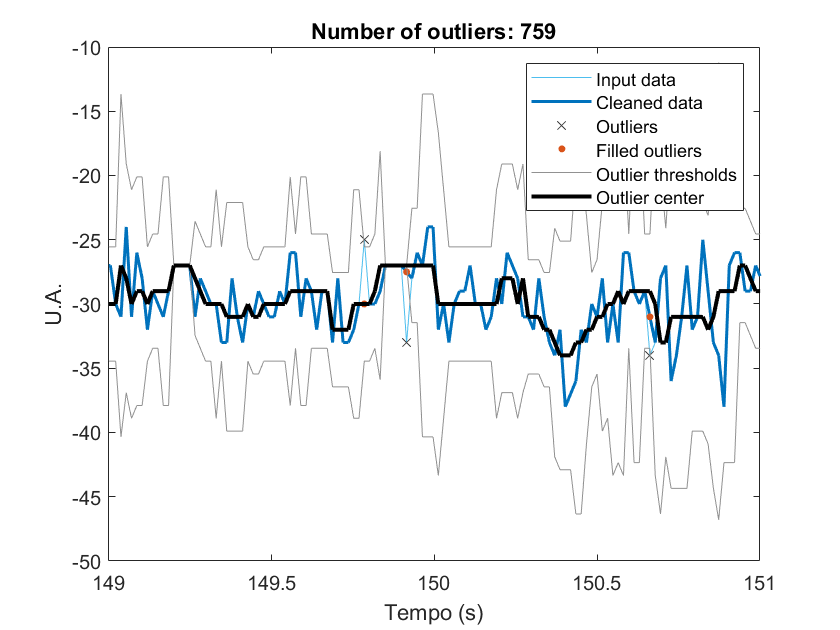

% Fill outliers
[cleanedData,outlierIndices11,thresholdLow11,thresholdHigh11,center11] = ...
    filloutliers(data,"linear","movmedian",0.098,"SamplePoints",time);

% Display results
clf
plot(time,data,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(time,cleanedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Cleaned data")

% Plot outliers
plot(time(outlierIndices11),data(outlierIndices11),"x","Color",[64 64 64]/255,...
    "DisplayName","Outliers")
title("Number of outliers: " + nnz(outlierIndices11))

% Plot filled outliers
plot(time(outlierIndices11),cleanedData(outlierIndices11),".","MarkerSize",12,...
    "Color",[217 83 25]/255,"DisplayName","Filled outliers")

% Plot outlier thresholds
plot([time(:); missing; time(:)],[thresholdHigh11(:); missing; thresholdLow11(:)],...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

% Plot outlier center
plot(time,center11,"k","LineWidth",2,"DisplayName","Outlier center")

hold off
legend
xlabel("time")
clear outlierIndices11 thresholdLow11 thresholdHigh11 center11
saveas(gcf,"output/Accelerometer (3rd Sample) outliers.jpeg")
saveas(gcf,"output/Accelerometer (3rd Sample) outliers.fig")
xlim([149,151])
xlabel("Tempo (s)")
ylabel("U.A.")

accel_data3.step1 = cleanedData;
clear cleanedData data time

#### Accelerometer sample 4

data = accel_data4.z;
time = accel_data4.t;

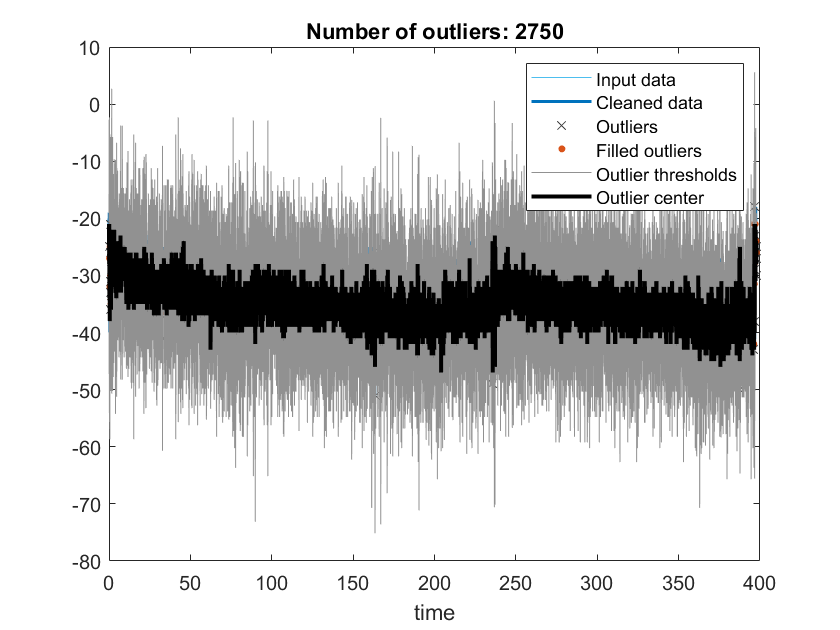

% Fill outliers
[cleanedData,outlierIndices12,thresholdLow12,thresholdHigh12,center12] = ...
    filloutliers(data,"linear","movmedian",0.049,"SamplePoints",time);

% Display results
clf
plot(time,data,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(time,cleanedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Cleaned data")

% Plot outliers
plot(time(outlierIndices12),data(outlierIndices12),"x","Color",[64 64 64]/255,...
    "DisplayName","Outliers")
title("Number of outliers: " + nnz(outlierIndices12))

% Plot filled outliers
plot(time(outlierIndices12),cleanedData(outlierIndices12),".","MarkerSize",12,...
    "Color",[217 83 25]/255,"DisplayName","Filled outliers")

% Plot outlier thresholds
plot([time(:); missing; time(:)],[thresholdHigh12(:); missing; thresholdLow12(:)],...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

% Plot outlier center
plot(time,center12,"k","LineWidth",2,"DisplayName","Outlier center")

hold off
legend
xlabel("time")
clear outlierIndices12 thresholdLow12 thresholdHigh12 center12
saveas(gcf,"output/Accelerometer (4th Sample) outliers.jpeg")

saveas(gcf,"output/Accelerometer (4th Sample) outliers.fig")
accel_data4.step1 = cleanedData;
clear cleanedData data time

#### Outputting graphs

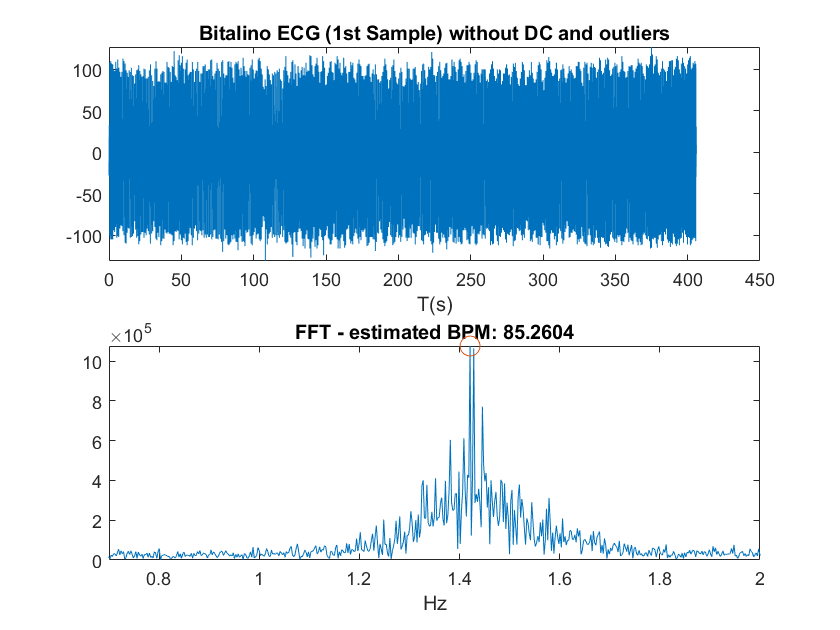

custom_fft(bitalino_data1.ecg_step1-mean(bitalino_data1.ecg_step1), bitalino_data1.t, bitalino_Fs, "Bitalino ECG (1st Sample) without DC and outliers", "BPM");

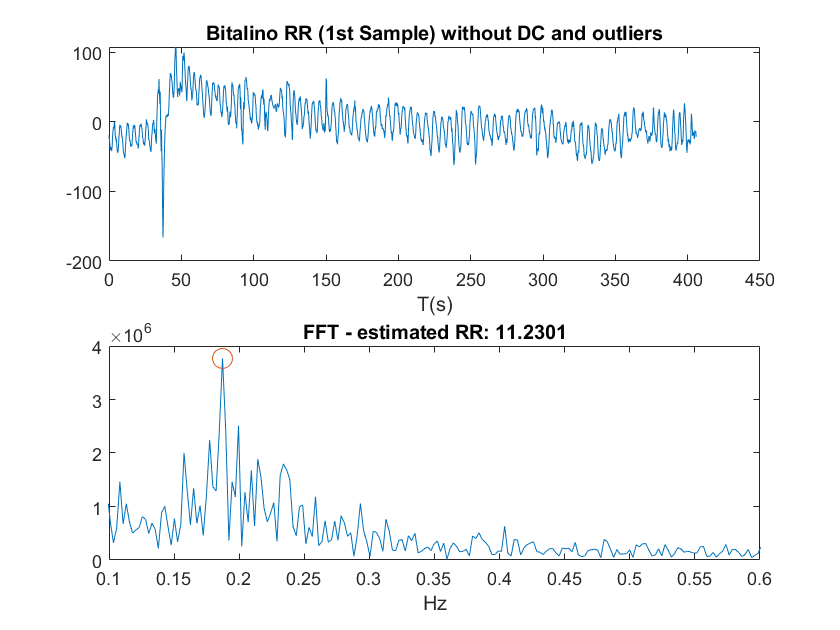

custom_fft(bitalino_data1.rr_step1-mean(bitalino_data1.rr_step1), bitalino_data1.t, bitalino_Fs, "Bitalino RR (1st Sample) without DC and outliers", "RR");

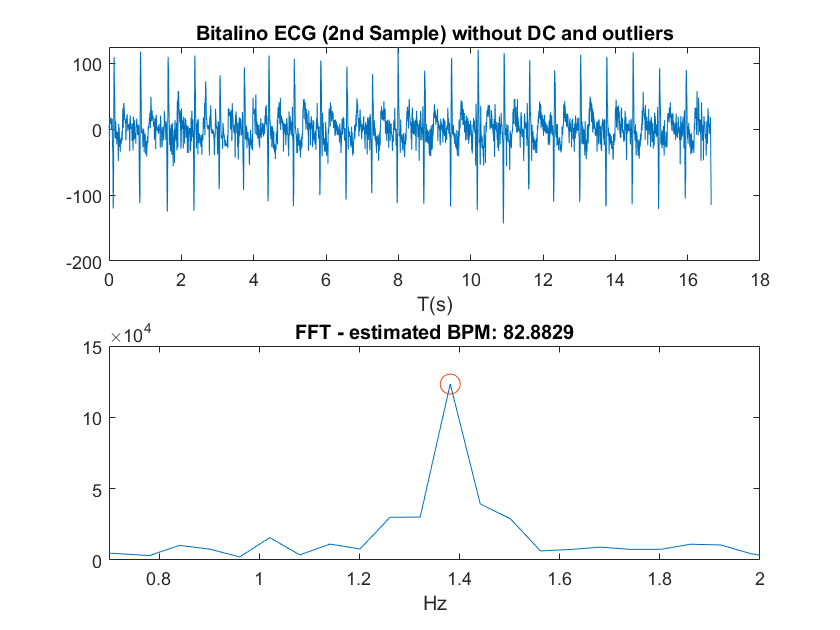

custom_fft(bitalino_data2.ecg_step1-mean(bitalino_data2.ecg_step1), bitalino_data2.t, bitalino_Fs, "Bitalino ECG (2nd Sample) without DC and outliers", "BPM");

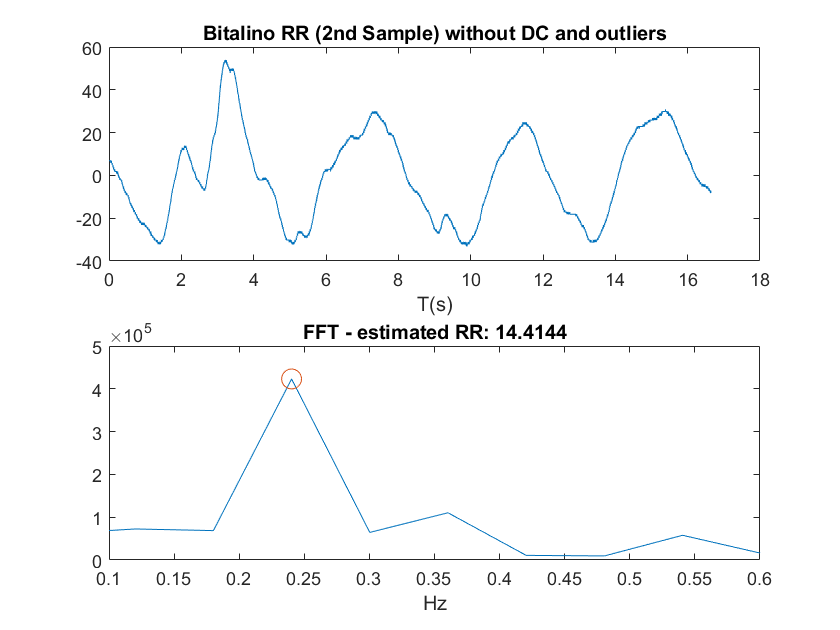

custom_fft(bitalino_data2.rr_step1-mean(bitalino_data2.rr_step1), bitalino_data2.t, bitalino_Fs, "Bitalino RR (2nd Sample) without DC and outliers", "RR");

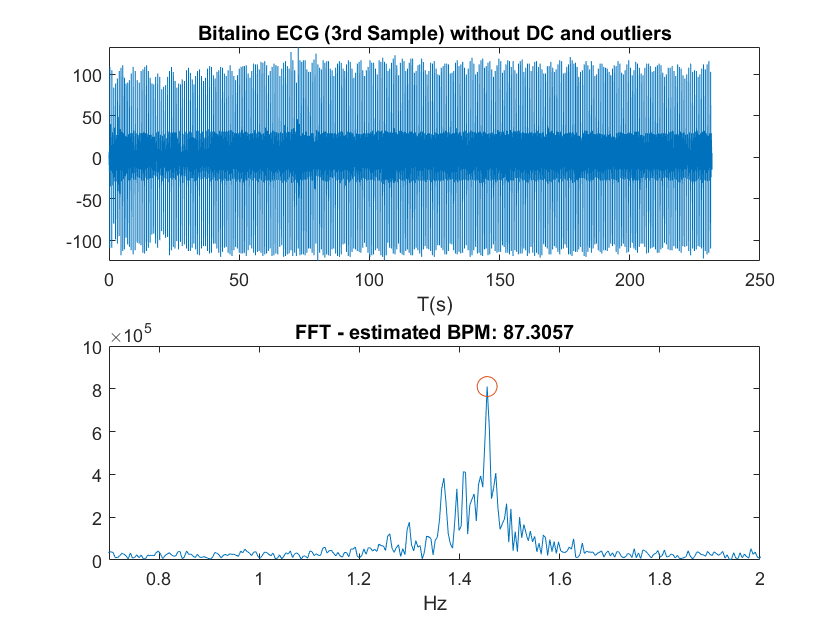

custom_fft(bitalino_data3.ecg_step1-mean(bitalino_data3.ecg_step1), bitalino_data3.t, bitalino_Fs, "Bitalino ECG (3rd Sample) without DC and outliers", "BPM");

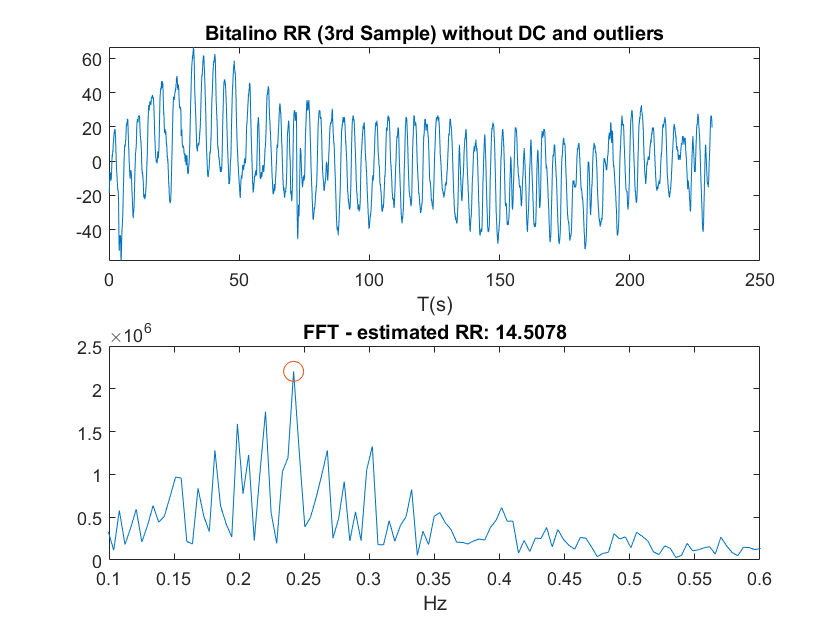

custom_fft(bitalino_data3.rr_step1-mean(bitalino_data3.rr_step1), bitalino_data3.t, bitalino_Fs, "Bitalino RR (3rd Sample) without DC and outliers", "RR");

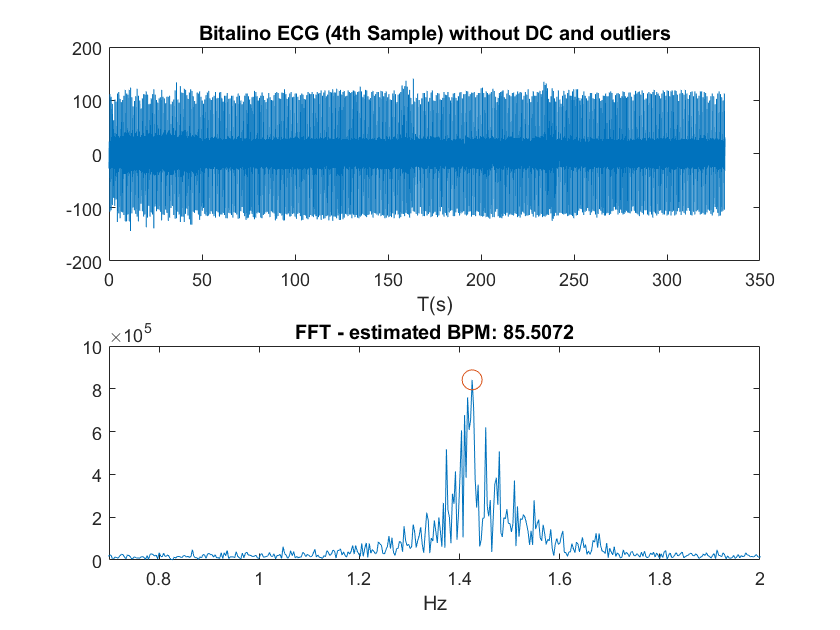

custom_fft(bitalino_data4.ecg_step1-mean(bitalino_data4.ecg_step1), bitalino_data4.t, bitalino_Fs, "Bitalino ECG (4th Sample) without DC and outliers", "BPM");

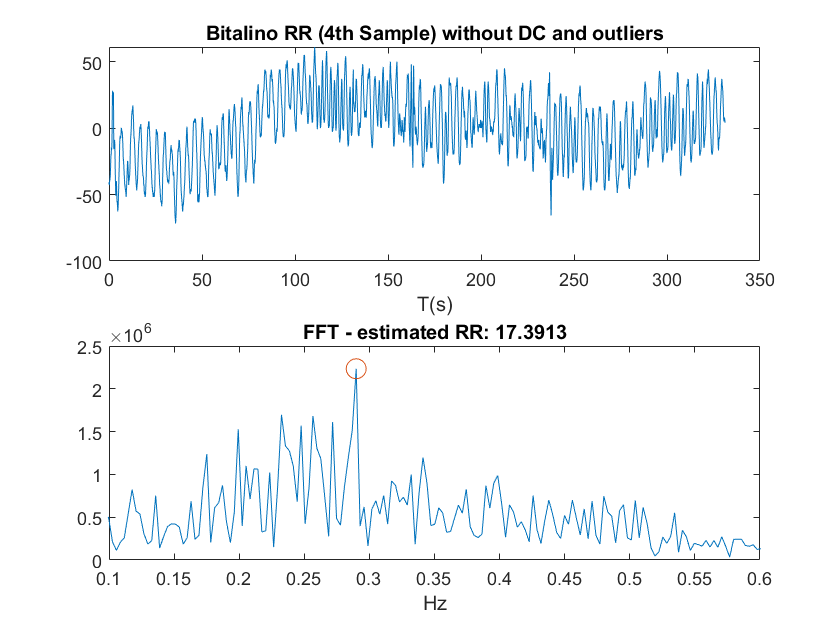

custom_fft(bitalino_data4.rr_step1-mean(bitalino_data4.rr_step1), bitalino_data4.t, bitalino_Fs, "Bitalino RR (4th Sample) without DC and outliers", "RR");

Estimated RR: 10.5369
Estimated BPM: 50.3714


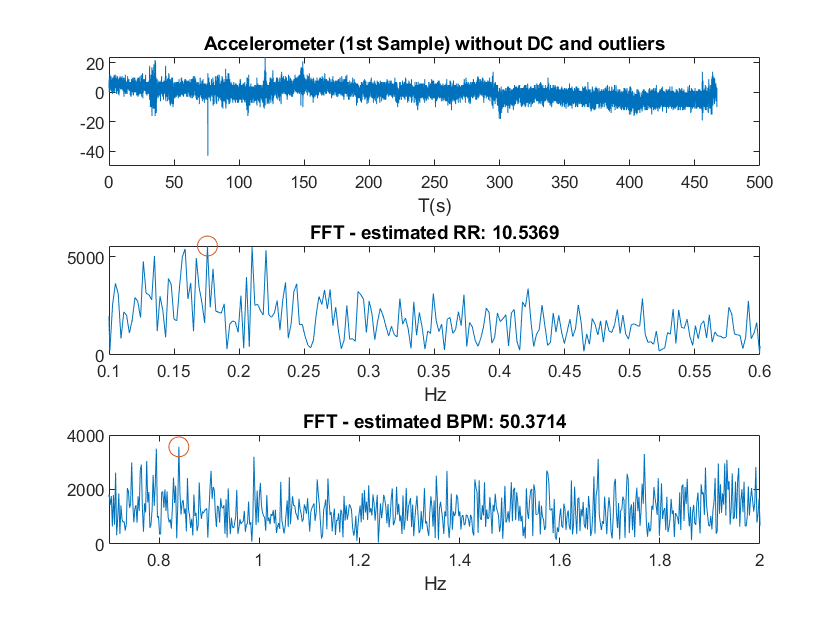


custom_fft(accel_data1.step1-mean(accel_data1.step1), accel_data1.t, accel_data1.fs, "Accelerometer (1st Sample) without DC and outliers", "ALL");

Estimated RR: 14.5566
Estimated BPM: 116.0368


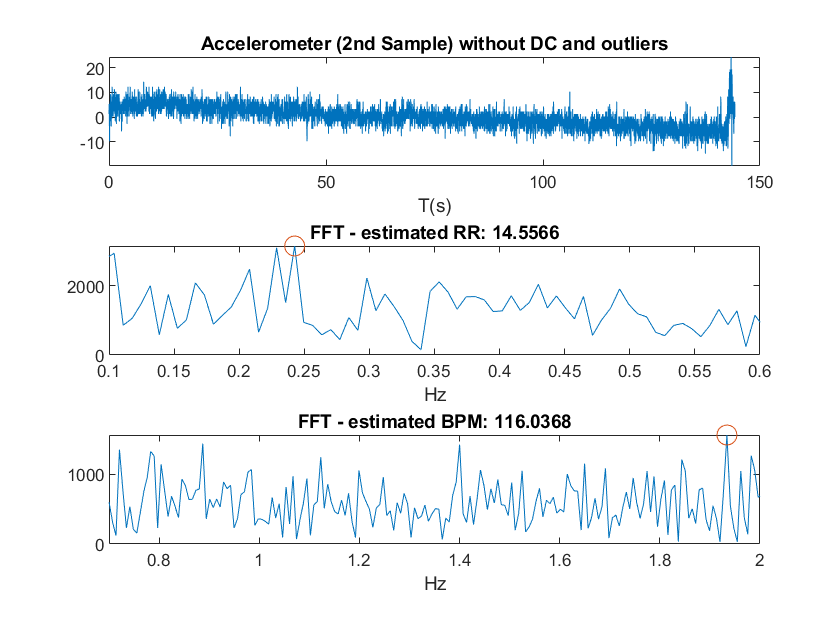

custom_fft(accel_data2.step1-mean(accel_data2.step1), accel_data2.t, accel_data2.fs, "Accelerometer (2nd Sample) without DC and outliers", "ALL");

Estimated RR: 6.0135
Estimated BPM: 44.3498


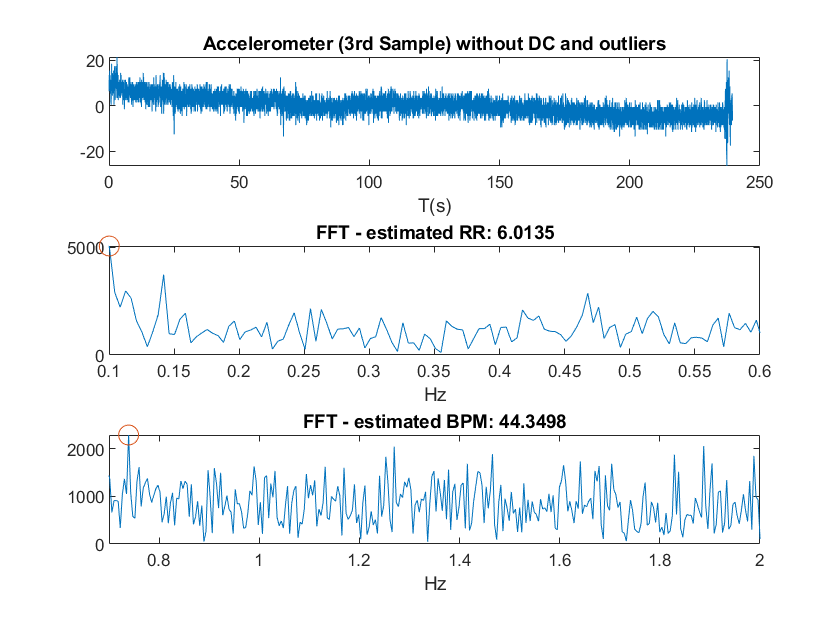

custom_fft(accel_data3.step1-mean(accel_data3.step1), accel_data3.t, accel_data3.fs, "Accelerometer (3rd Sample) without DC and outliers", "ALL");

Estimated RR: 13.5736
Estimated BPM: 60.0254


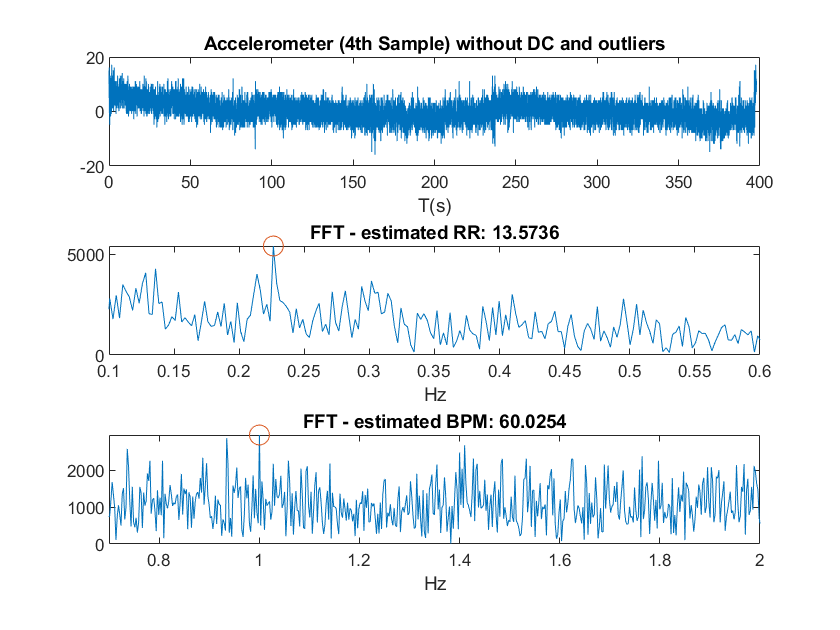

custom_fft(accel_data4.step1-mean(accel_data4.step1), accel_data4.t, accel_data4.fs, "Accelerometer (4th Sample) without DC and outliers", "ALL");

## IIR Filters

#### Bitalino sample 1

Hd = butter_ecg(bitalino_Fs);
bitalino_data1.ecg_step2 = filter(Hd,bitalino_data1.ecg_step1);
Hd = butter_rr(bitalino_Fs);
bitalino_data1.rr_step2 = filter(Hd,bitalino_data1.rr_step1);
clear Hd

#### Bitalino sample 2

Hd = butter_ecg(bitalino_Fs);
bitalino_data2.ecg_step2 = filter(Hd,bitalino_data2.ecg_step1);
Hd = butter_rr(bitalino_Fs);
bitalino_data2.rr_step2 = filter(Hd,bitalino_data2.rr_step1);
clear Hd

#### Bitalino sample 3

Hd = butter_ecg(bitalino_Fs);
bitalino_data3.ecg_step2 = filter(Hd,bitalino_data3.ecg_step1);
Hd = butter_rr(bitalino_Fs);
bitalino_data3.rr_step2 = filter(Hd,bitalino_data3.rr_step1);
clear Hd

#### Bitalino sample 4

Hd = butter_ecg(bitalino_Fs);
bitalino_data4.ecg_step2 = filter(Hd,bitalino_data4.ecg_step1);
Hd = butter_rr(bitalino_Fs);
bitalino_data4.rr_step2 = filter(Hd,bitalino_data4.rr_step1);
clear Hd

#### Accelerometer sample 1

%Hd = butter_ecg(accel_data1.fs)
%accel_data1.ecg_step2 = filter(Hd,accel_data1.step1);
%Hd = butter_rr(accel_data1.fs);
%accel_data1.rr_step2 = filter(Hd,accel_data1.step1);
%clear Hd
accel_data1.ecg_step2 = cheby_bpm(accel_data1.step1);
accel_data1.rr_step2 = filter_rr(accel_data1.step1);

#### Accelerometer sample 2

Hd = butter_ecg(accel_data2.fs);
accel_data2.ecg_step2 = filter(Hd,accel_data2.step1);
Hd = butter_rr(accel_data2.fs);
accel_data2.rr_step2 = filter(Hd,accel_data2.step1);
clear Hd

#### Accelerometer sample 3

Hd = butter_ecg(accel_data3.fs);
accel_data3.ecg_step2 = filter(Hd,accel_data3.step1);
Hd = butter_rr(accel_data3.fs);
accel_data3.rr_step2 = filter(Hd,accel_data3.step1);
clear Hd

#### Accelerometer sample 4

Hd = butter_ecg(accel_data4.fs);
accel_data4.ecg_step2 = filter(Hd,accel_data4.step1);
Hd = butter_rr(accel_data4.fs);
accel_data4.rr_step2 = filter(Hd,accel_data4.step1);
clear Hd

#### Outputting graphs

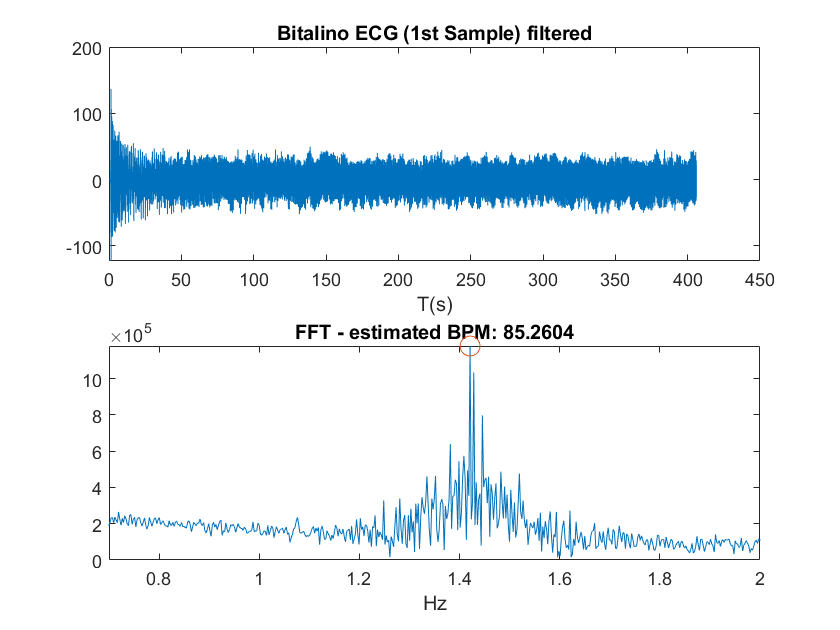

custom_fft(bitalino_data1.ecg_step2, bitalino_data1.t, bitalino_Fs, "Bitalino ECG (1st Sample) filtered", "BPM");

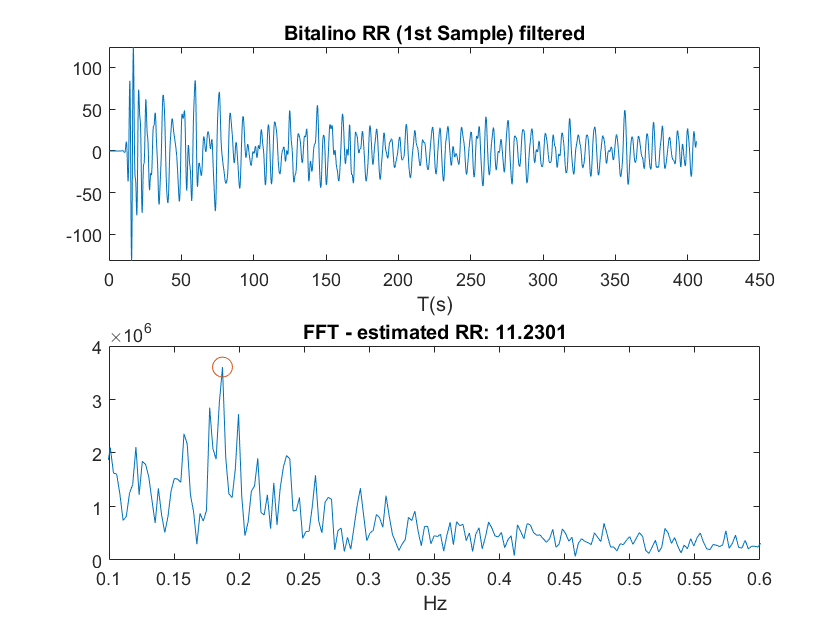

custom_fft(bitalino_data1.rr_step2, bitalino_data1.t, bitalino_Fs, "Bitalino RR (1st Sample) filtered", "RR");

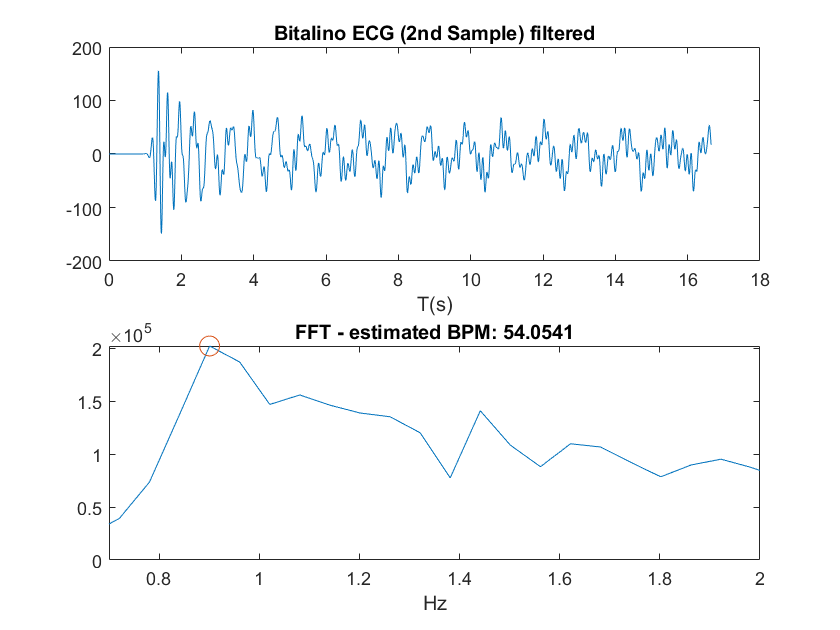

custom_fft(bitalino_data2.ecg_step2, bitalino_data2.t, bitalino_Fs, "Bitalino ECG (2nd Sample) filtered", "BPM");

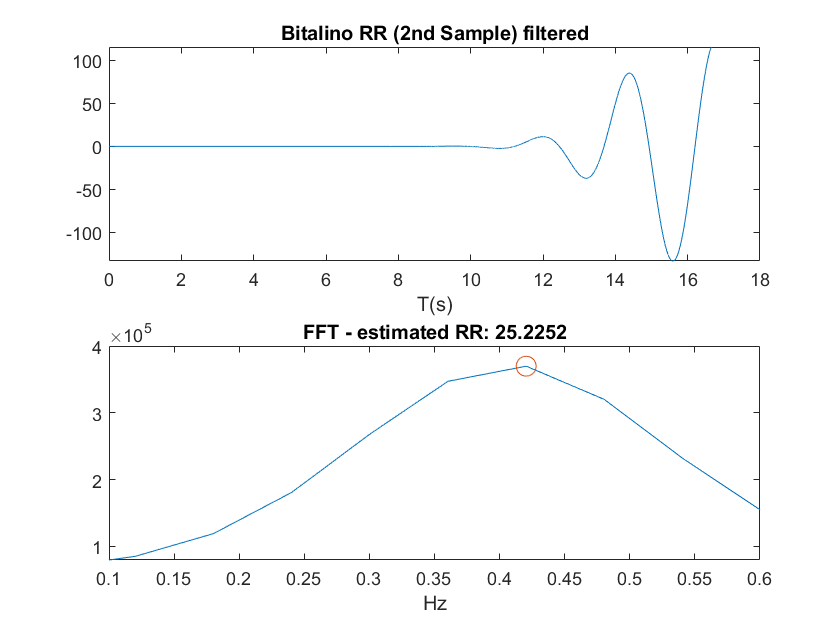

custom_fft(bitalino_data2.rr_step2, bitalino_data2.t, bitalino_Fs, "Bitalino RR (2nd Sample) filtered", "RR");

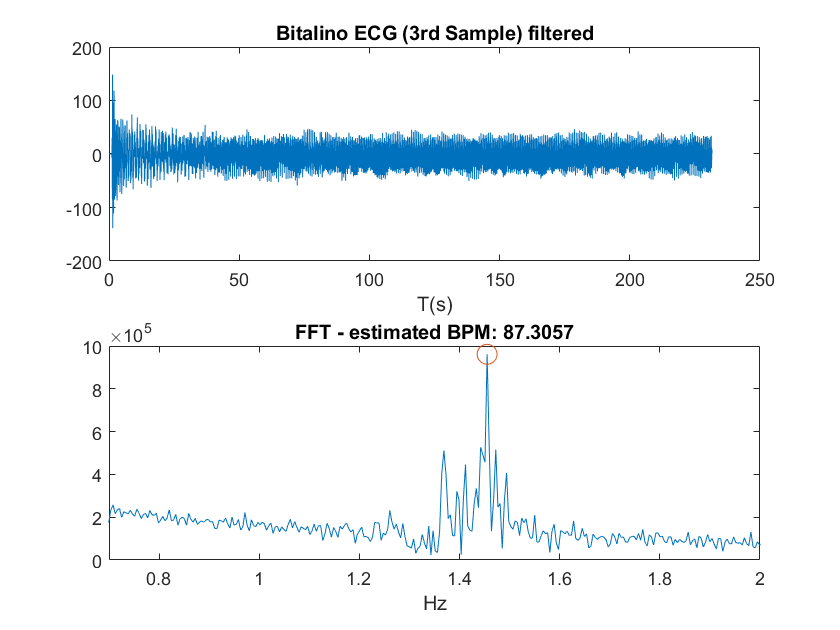

custom_fft(bitalino_data3.ecg_step2, bitalino_data3.t, bitalino_Fs, "Bitalino ECG (3rd Sample) filtered", "BPM");

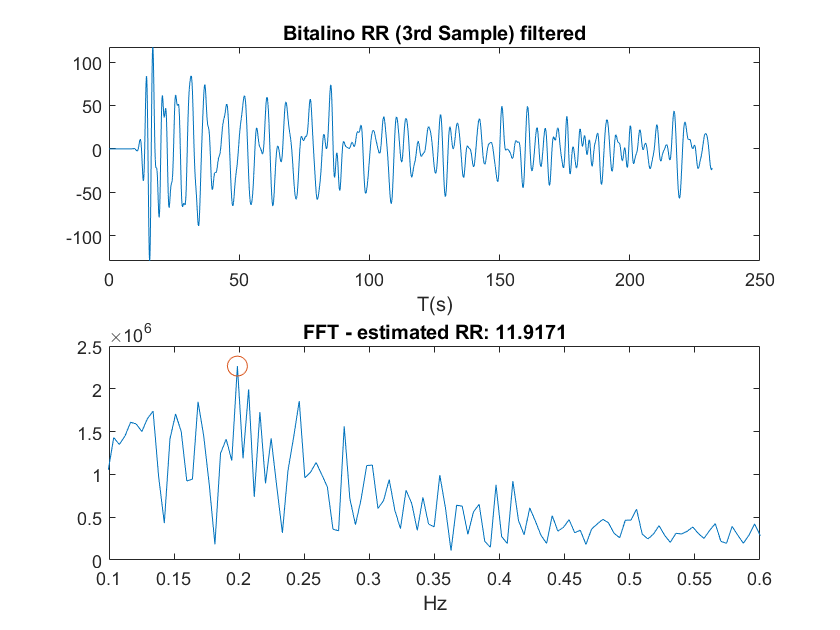

custom_fft(bitalino_data3.rr_step2, bitalino_data3.t, bitalino_Fs, "Bitalino RR (3rd Sample) filtered", "RR");

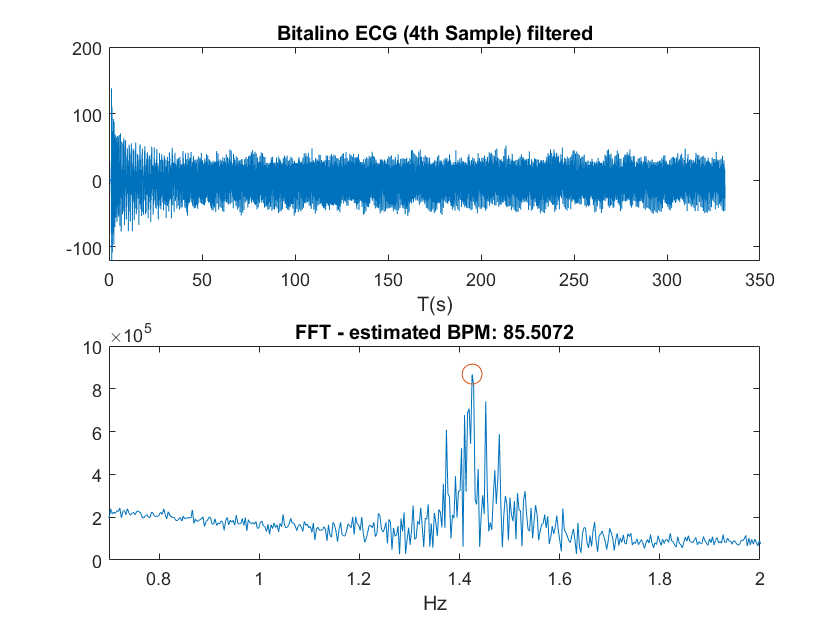

custom_fft(bitalino_data4.ecg_step2, bitalino_data4.t, bitalino_Fs, "Bitalino ECG (4th Sample) filtered", "BPM");

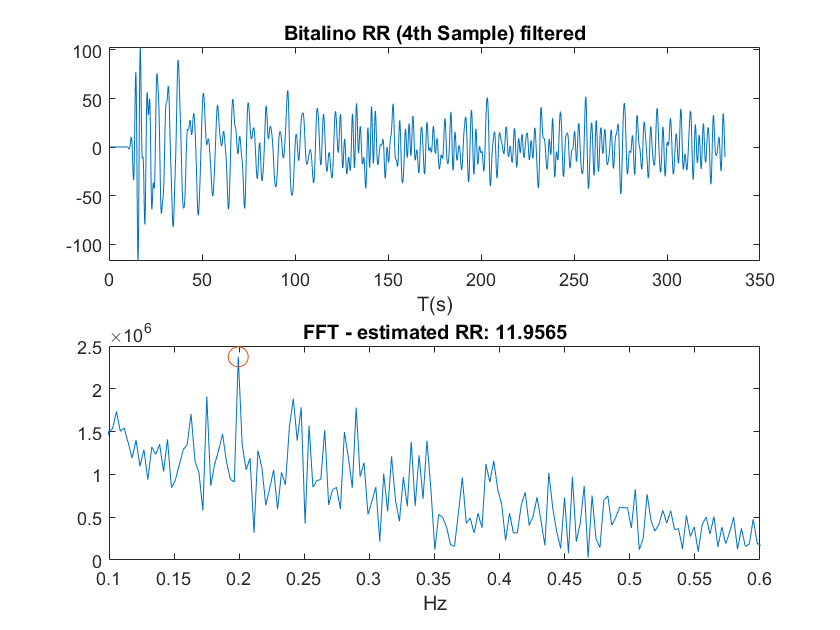

custom_fft(bitalino_data4.rr_step2, bitalino_data4.t, bitalino_Fs, "Bitalino RR (4th Sample) filtered", "RR");

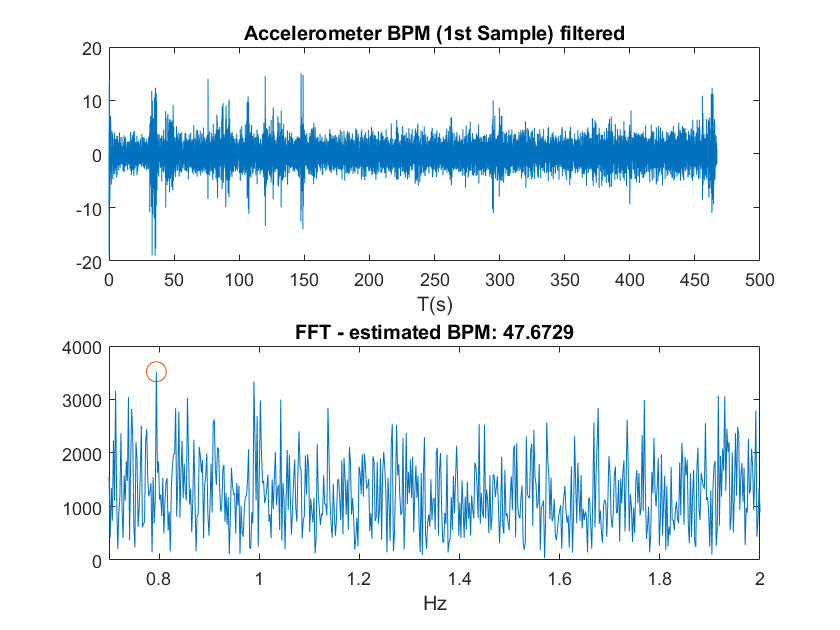


custom_fft(accel_data1.ecg_step2, accel_data1.t, accel_data1.fs, "Accelerometer BPM (1st Sample) filtered", "BPM");

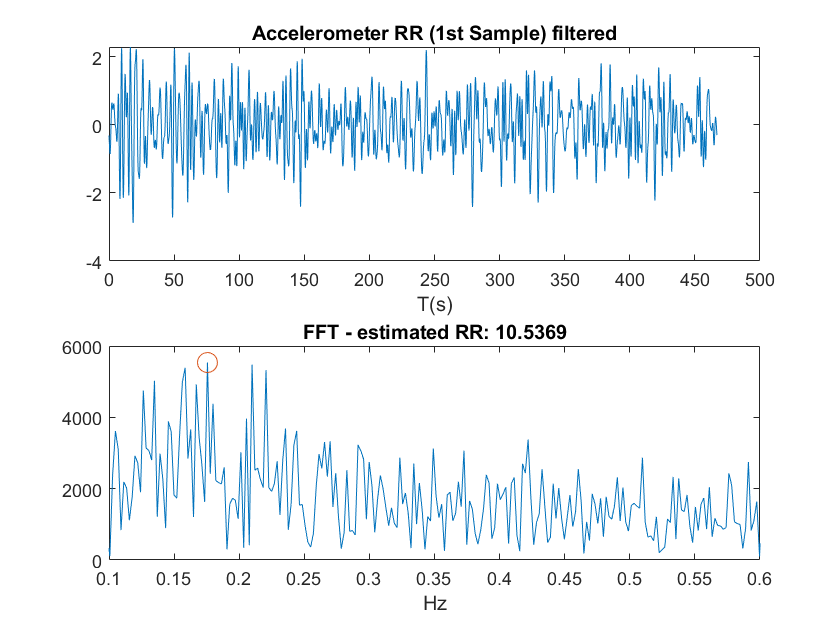

custom_fft(accel_data1.rr_step2, accel_data1.t, accel_data1.fs, "Accelerometer RR (1st Sample) filtered", "RR");

custom_fft(accel_data2.ecg_step2, accel_data2.t, accel_data2.fs, "Accelerometer BPM (2nd Sample) filtered", "BPM");

Unrecognized field name "ecg_step2".

custom_fft(accel_data2.rr_step2, accel_data2.t, accel_data2.fs, "Accelerometer RR (2nd Sample) filtered", "RR");
custom_fft(accel_data3.ecg_step2, accel_data3.t, accel_data3.fs, "Accelerometer BPM (3rd Sample) filtered", "BPM");
custom_fft(accel_data3.rr_step2, accel_data3.t, accel_data3.fs, "Accelerometer RR (3rd Sample) filtered", "RR");
custom_fft(accel_data4.ecg_step2, accel_data4.t, accel_data4.fs, "Accelerometer BPM (4th Sample) filtered", "BPM");
custom_fft(accel_data4.rr_step2, accel_data4.t, accel_data4.fs, "Accelerometer RR (4th Sample) filtered", "RR");

## -----------------------------------------------------------------------

##                               Respiration Rate

## -----------------------------------------------------------------------

## Moving average smoothing filter (3 seconds)

#### Bitalino sample 1

data = bitalino_data1.rr_step2;
time = bitalino_data1.t;

% Smooth input data
smoothedData = smoothdata(data,"movmean",3,"SamplePoints",time);

% Display results
clf
plot(time,data,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(time,smoothedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend
xlabel("time")
bitalino_data1.rr_step3 = smoothedData;
clear data time smoothedData

#### Bitalino sample 2

data = bitalino_data2.rr_step2;
time = bitalino_data2.t;

% Smooth input data
smoothedData = smoothdata(data,"movmean",3,"SamplePoints",time);

% Display results
clf
plot(time,data,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(time,smoothedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend
xlabel("time")
bitalino_data2.rr_step3 = smoothedData;
clear data time smoothedData

#### Bitalino sample 3

data = bitalino_data3.rr_step2;
time = bitalino_data3.t;

% Smooth input data
smoothedData = smoothdata(data,"movmean",3,"SamplePoints",time);

% Display results
clf
plot(time,data,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(time,smoothedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend
xlabel("time")
bitalino_data3.rr_step3 = smoothedData;
ylabel("U.A."),xlabel("Tempo (s)")
xlim([30,70])
clear data time smoothedData

#### Bitalino sample 4

data = bitalino_data4.rr_step2;
time = bitalino_data4.t;

% Smooth input data
smoothedData = smoothdata(data,"movmean",3,"SamplePoints",time);

% Display results
clf
plot(time,data,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(time,smoothedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend
xlabel("time")
bitalino_data4.rr_step3 = smoothedData;
clear data time smoothedData

#### Accelerometer sample 1

data = accel_data1.rr_step2;
time = accel_data1.t;

% Smooth input data
smoothedData = smoothdata(data,"movmean",3,"SamplePoints",time);

% Display results
clf
plot(time,data,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(time,smoothedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend
xlabel("time")
accel_data1.rr_step3 = smoothedData;
clear data time smoothedData

#### Accelerometer sample 2

data = accel_data2.rr_step2;
time = accel_data2.t;

% Smooth input data
smoothedData = smoothdata(data,"movmean",3,"SamplePoints",time);

% Display results
clf
plot(time,data,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(time,smoothedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend
xlabel("time")
accel_data2.rr_step3 = smoothedData;
clear data time smoothedData

#### Accelerometer sample 3

data = accel_data3.rr_step2;
time = accel_data3.t;

% Smooth input data
smoothedData = smoothdata(data,"movmean",3,"SamplePoints",time);

% Display results
clf
plot(time,data,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(time,smoothedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend
xlabel("time")
accel_data3.rr_step3 = smoothedData;
clear data time smoothedData

#### Accelerometer sample 4

data = accel_data4.rr_step2;
time = accel_data4.t;

% Smooth input data
smoothedData = smoothdata(data,"movmean",4,"SamplePoints",time);

% Display results
clf
plot(time,data,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(time,smoothedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend
xlabel("time")
accel_data4.rr_step3 = smoothedData;
clear data time smoothedData

## Finding peaks

#### Bitalino sample 1

data = bitalino_data1.rr_step3;
time = bitalino_data1.t;
maxIndices = custom_local_maxima_rr(data,time);
bitalino_data1.rr_step4_mean = sum(maxIndices)/max(time)*60;
bitalino_data1.rr_step4_array = 1./diff(time(maxIndices))*60;
clear data time maxIndices

#### Bitalino sample 2

data = bitalino_data2.rr_step3;
time = bitalino_data2.t;
maxIndices = custom_local_maxima_rr(data,time);
bitalino_data2.rr_step4_mean = sum(maxIndices)/max(time)*60;
bitalino_data2.rr_step4_array = 1./diff(time(maxIndices))*60;
clear data time maxIndices

#### Bitalino sample 3

data = bitalino_data3.rr_step3;
time = bitalino_data3.t;
maxIndices = custom_local_maxima_rr(data,time);
bitalino_data3.rr_step4_mean = sum(maxIndices)/max(time)*60;
bitalino_data3.rr_step4_array = 1./diff(time(maxIndices))*60;
xlabel("Tempo (s)")
ylabel("U.A.")
xlim([30,70])
clear data time maxIndices

#### Bitalino sample 4

data = bitalino_data4.rr_step3;
time = bitalino_data4.t;
maxIndices = custom_local_maxima_rr(data,time);
bitalino_data4.rr_step4_mean = sum(maxIndices)/max(time)*60;
bitalino_data4.rr_step4_array = 1./diff(time(maxIndices))*60;
clear data time maxIndices

#### Accelerometer sample 1

data = accel_data1.rr_step3;
time = accel_data1.t;
maxIndices = custom_local_maxima_rr(data,time);
accel_data1.rr_step4_mean = sum(maxIndices)/max(time)*60;
accel_data1.rr_step4_array = 1./diff(time(maxIndices))*60;
clear data time maxIndices
custom_fft(accel_data1.rr_step3, accel_data1.t, accel_data1.fs,"test","RR")

#### Accelerometer sample 2

data = accel_data2.rr_step3;
time = accel_data2.t;
maxIndices = custom_local_maxima_rr(data,time);
accel_data2.rr_step4_mean = sum(maxIndices)/max(time)*60;
accel_data2.rr_step4_array = 1./diff(time(maxIndices))*60;
clear data time maxIndices

#### Accelerometer sample 3

data = accel_data3.rr_step3;
time = accel_data3.t;
maxIndices = custom_local_maxima_rr(data,time);
accel_data3.rr_step4_mean = sum(maxIndices)/max(time)*60;
accel_data3.rr_step4_array = 1./diff(time(maxIndices))*60;
clear data time maxIndices

#### Accelerometer sample 4

data = accel_data4.rr_step3;
time = accel_data4.t;
maxIndices = custom_local_maxima_rr(data,time);
accel_data4.rr_step4_mean = sum(maxIndices)/max(time)*60;
accel_data4.rr_step4_array = 1./diff(time(maxIndices))*60;
clear data time maxIndices

## -----------------------------------------------------------------------

##                         Heartbeats per minute

## -----------------------------------------------------------------------

## Segmentation

#### Bitalino sample 1

windowRoll = bitalino_Fs * 15;
windowSize = windowRoll*4;
[output, time] = segment_data(bitalino_data1.ecg_step2, bitalino_data1.t,windowSize,windowRoll);
bitalino_data1.ecg_step3 = output;
bitalino_data1.t_array = time;
[output, ~] = segment_data(bitalino_data1.rr_step2, bitalino_data1.t,windowSize,windowRoll);
bitalino_data1.rr_step3 = output;
clear output time

#### Bitalino sample 2

windowRoll = bitalino_Fs * 15;
windowSize = windowRoll*4;
[output, time] = segment_data(bitalino_data2.ecg_step2, bitalino_data2.t,windowSize,windowRoll);
bitalino_data2.ecg_step3 = output;
bitalino_data2.t_array = time;
[output, ~] = segment_data(bitalino_data2.rr_step2, bitalino_data2.t,windowSize,windowRoll);
bitalino_data2.rr_step3 = output;
clear output time

#### Bitalino sample 3

windowRoll = bitalino_Fs * 15;
windowSize = windowRoll*4;
[output, time] = segment_data(bitalino_data3.ecg_step2, bitalino_data3.t,windowSize,windowRoll);
bitalino_data3.ecg_step3 = output;
bitalino_data3.t_array = time;
[output, ~] = segment_data(bitalino_data3.rr_step2, bitalino_data3.t,windowSize,windowRoll);
bitalino_data3.rr_step3 = output;
clear output time

#### Bitalino sample 4

windowRoll = bitalino_Fs * 15;
windowSize = windowRoll*4;
[output, time] = segment_data(bitalino_data4.ecg_step2, bitalino_data4.t,windowSize,windowRoll);
bitalino_data4.ecg_step3 = output;
bitalino_data4.t_array = time;
[output, ~] = segment_data(bitalino_data4.rr_step2, bitalino_data4.t,windowSize,windowRoll);
bitalino_data4.rr_step3 = output;
clear output time

#### Accelerometer sample 4

windowRoll = accel_data1.fs * 15;
windowSize = windowRoll*4;
[output, time] = segment_data(bitalino_data4.ecg_step2, bitalino_data4.t,windowSize,windowRoll);
bitalino_data4.ecg_step3 = output;
bitalino_data4.t_array = time;
[output, ~] = segment_data(bitalino_data4.rr_step2, bitalino_data4.t,windowSize,windowRoll);
bitalino_data4.rr_step3 = output;
clear output time